# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                       ex1.mlx                 featureNormalize.m      normalEqn.m             warmUpExercise.m        
..                      ex1_companion.mlx       gradientDescent.m       plotData.m              
computeCost.m           ex1data1.txt            gradientDescentMulti.m  submit.m                
computeCostMulti.m      ex1data2.txt            lib                     token.mat               



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

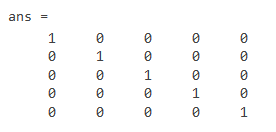

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

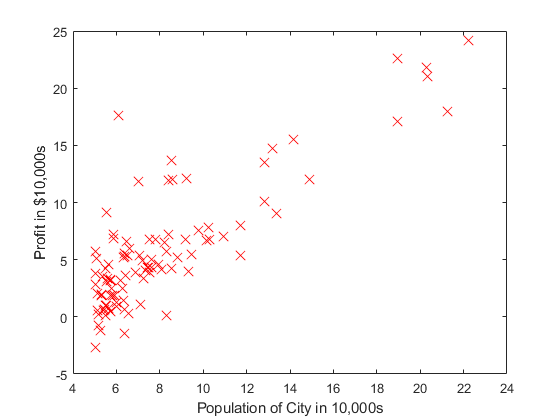

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

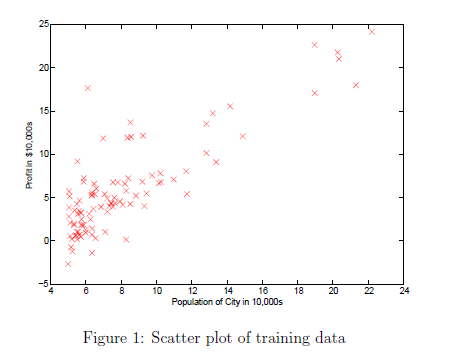

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

h =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


J = 32.0727

ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

h =    11.2202
   10.0554
   16.0372
   13.0064
   10.7196
   15.7658
   13.9528
   16.1562
   11.9724
    9.1092


J = 54.2425

ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

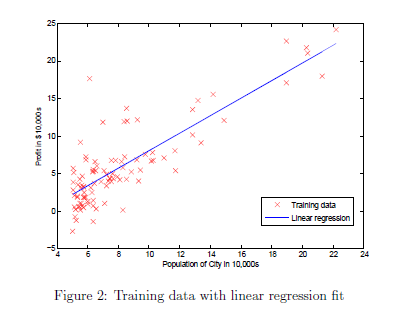    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

h =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


theta =     0.0584
    0.6533


h =     4.0500
    3.6696
    5.6235
    4.6335
    3.8865
    5.5348
    4.9426
    5.6624
    4.2958
    3.3605


J = 6.7372

h =     4.0500
    3.6696
    5.6235
    4.6335
    3.8865
    5.5348
    4.9426
    5.6624
    4.2958
    3.3605


theta =     0.0629
    0.7700


h =     4.7677
    4.3193
    6.6223
    5.4554
    4.5750
    6.5178
    5.8198
    6.6681
    5.0573
    3.9550


J = 5.9316

h =     4.7677
    4.3193
    6.6223
    5.4554
    4.5750
    6.5178
    5.8198
    6.6681
    5.0573
    3.9550


theta =     0.0578
    0.7913


h =     4.8930
    4.4322
    6.7990
    5.5998
    4.6950
    6.6916
    5.9743
    6.8461
    5.1907
    4.0578


J = 5.9012

h =     4.8930
    4.4322
    6.7990
    5.5998
    4.6950
    6.6916
    5.9743
    6.8461
    5.1907
    4.0578


theta =     0.0511
    0.7957


h =     4.9131
    4.4496
    6.8296
    5.6237
    4.7139
    6.7216
    6.0003
    6.8769
    5.2123
    4.0732


J = 5.8952

h =     4.9131
    4.4496
    6.8296
    5.6237
    4.7139
    6.7216
    6.0003
    6.8769
    5.2123
    4.0732


theta =     0.0440
    0.7971


h =     4.9144
    4.4501
    6.8342
    5.6262
    4.7148
    6.7260
    6.0034
    6.8816
    5.2141
    4.0730


J = 5.8901

h =     4.9144
    4.4501
    6.8342
    5.6262
    4.7148
    6.7260
    6.0034
    6.8816
    5.2141
    4.0730


theta =     0.0369
    0.7979


h =     4.9123
    4.4476
    6.8341
    5.6250
    4.7126
    6.7259
    6.0025
    6.8816
    5.2124
    4.0701


J = 5.8850

h =     4.9123
    4.4476
    6.8341
    5.6250
    4.7126
    6.7259
    6.0025
    6.8816
    5.2124
    4.0701


theta =     0.0298
    0.7987


h =     4.9097
    4.4446
    6.8333
    5.6230
    4.7098
    6.7249
    6.0009
    6.8808
    5.2101
    4.0667


J = 5.8799

h =     4.9097
    4.4446
    6.8333
    5.6230
    4.7098
    6.7249
    6.0009
    6.8808
    5.2101
    4.0667


theta =     0.0228
    0.7994


h =     4.9070
    4.4415
    6.8323
    5.6209
    4.7069
    6.7238
    5.9992
    6.8799
    5.2077
    4.0633


J = 5.8749

h =     4.9070
    4.4415
    6.8323
    5.6209
    4.7069
    6.7238
    5.9992
    6.8799
    5.2077
    4.0633


theta =     0.0157
    0.8001


h =     4.9043
    4.4383
    6.8313
    5.6188
    4.7040
    6.7227
    5.9974
    6.8789
    5.2052
    4.0598


J = 5.8698

h =     4.9043
    4.4383
    6.8313
    5.6188
    4.7040
    6.7227
    5.9974
    6.8789
    5.2052
    4.0598


theta =     0.0086
    0.8008


h =     4.9016
    4.4352
    6.8303
    5.6167
    4.7011
    6.7216
    5.9957
    6.8779
    5.2027
    4.0563


J = 5.8648

h =     4.9016
    4.4352
    6.8303
    5.6167
    4.7011
    6.7216
    5.9957
    6.8779
    5.2027
    4.0563


theta =     0.0016
    0.8015


h =     4.8988
    4.4321
    6.8293
    5.6147
    4.6982
    6.7205
    5.9939
    6.8769
    5.2003
    4.0529


J = 5.8598

h =     4.8988
    4.4321
    6.8293
    5.6147
    4.6982
    6.7205
    5.9939
    6.8769
    5.2003
    4.0529


theta =    -0.0054
    0.8022


h =     4.8961
    4.4289
    6.8282
    5.6126
    4.6953
    6.7194
    5.9922
    6.8760
    5.1978
    4.0494


J = 5.8548

h =     4.8961
    4.4289
    6.8282
    5.6126
    4.6953
    6.7194
    5.9922
    6.8760
    5.1978
    4.0494


theta =    -0.0124
    0.8029


h =     4.8934
    4.4258
    6.8272
    5.6105
    4.6925
    6.7183
    5.9904
    6.8750
    5.1954
    4.0460


J = 5.8499

h =     4.8934
    4.4258
    6.8272
    5.6105
    4.6925
    6.7183
    5.9904
    6.8750
    5.1954
    4.0460


theta =    -0.0194
    0.8036


h =     4.8907
    4.4227
    6.8262
    5.6084
    4.6896
    6.7172
    5.9887
    6.8740
    5.1930
    4.0425


J = 5.8449

h =     4.8907
    4.4227
    6.8262
    5.6084
    4.6896
    6.7172
    5.9887
    6.8740
    5.1930
    4.0425


theta =    -0.0264
    0.8043


h =     4.8880
    4.4196
    6.8252
    5.6064
    4.6867
    6.7161
    5.9870
    6.8731
    5.1905
    4.0391


J = 5.8400

h =     4.8880
    4.4196
    6.8252
    5.6064
    4.6867
    6.7161
    5.9870
    6.8731
    5.1905
    4.0391


theta = 2×1
   -0.0334
    0.8050


h = 97×1
    4.8853
    4.4165
    6.8242
    5.6043
    4.6838
    6.7150
    5.9852
    6.8721
    5.1881
    4.0356


J = 5.8351

h = 97×1
    4.8853
    4.4165
    6.8242
    5.6043
    4.6838
    6.7150
    5.9852
    6.8721
    5.1881
    4.0356


theta = 2×1
   -0.0404
    0.8057


h = 97×1
    4.8826
    4.4134
    6.8232
    5.6022
    4.6810
    6.7139
    5.9835
    6.8711
    5.1857
    4.0322


J = 5.8302

h = 97×1
    4.8826
    4.4134
    6.8232
    5.6022
    4.6810
    6.7139
    5.9835
    6.8711
    5.1857
    4.0322


theta = 2×1
   -0.0473
    0.8064


h = 97×1
    4.8800
    4.4103
    6.8222
    5.6002
    4.6781
    6.7128
    5.9818
    6.8702
    5.1832
    4.0288


J = 5.8253

h = 97×1
    4.8800
    4.4103
    6.8222
    5.6002
    4.6781
    6.7128
    5.9818
    6.8702
    5.1832
    4.0288


theta = 2×1
   -0.0542
    0.8071


h = 97×1
    4.8773
    4.4072
    6.8212
    5.5981
    4.6753
    6.7117
    5.9800
    6.8692
    5.1808
    4.0254


J = 5.8205

h = 97×1
    4.8773
    4.4072
    6.8212
    5.5981
    4.6753
    6.7117
    5.9800
    6.8692
    5.1808
    4.0254


theta = 2×1
   -0.0612
    0.8078


h = 97×1
    4.8746
    4.4041
    6.8202
    5.5961
    4.6724
    6.7106
    5.9783
    6.8683
    5.1784
    4.0220


J = 5.8156

h = 97×1
    4.8746
    4.4041
    6.8202
    5.5961
    4.6724
    6.7106
    5.9783
    6.8683
    5.1784
    4.0220


theta = 2×1
   -0.0681
    0.8085


h = 97×1
    4.8719
    4.4011
    6.8192
    5.5940
    4.6696
    6.7095
    5.9766
    6.8673
    5.1760
    4.0186


J = 5.8108

h = 97×1
    4.8719
    4.4011
    6.8192
    5.5940
    4.6696
    6.7095
    5.9766
    6.8673
    5.1760
    4.0186


theta = 2×1
   -0.0750
    0.8092


h = 97×1
    4.8693
    4.3980
    6.8182
    5.5920
    4.6667
    6.7084
    5.9749
    6.8664
    5.1736
    4.0152


J = 5.8060

h = 97×1
    4.8693
    4.3980
    6.8182
    5.5920
    4.6667
    6.7084
    5.9749
    6.8664
    5.1736
    4.0152


theta = 2×1
   -0.0819
    0.8099


h = 97×1
    4.8666
    4.3949
    6.8172
    5.5899
    4.6639
    6.7073
    5.9732
    6.8654
    5.1712
    4.0118


J = 5.8012

h = 97×1
    4.8666
    4.3949
    6.8172
    5.5899
    4.6639
    6.7073
    5.9732
    6.8654
    5.1712
    4.0118


theta = 2×1
   -0.0887
    0.8106


h = 97×1
    4.8640
    4.3919
    6.8162
    5.5879
    4.6611
    6.7062
    5.9714
    6.8645
    5.1688
    4.0084


J = 5.7965

h = 97×1
    4.8640
    4.3919
    6.8162
    5.5879
    4.6611
    6.7062
    5.9714
    6.8645
    5.1688
    4.0084


theta = 2×1
   -0.0956
    0.8113


h = 97×1
    4.8613
    4.3888
    6.8152
    5.5858
    4.6582
    6.7051
    5.9697
    6.8635
    5.1664
    4.0050


J = 5.7917

h = 97×1
    4.8613
    4.3888
    6.8152
    5.5858
    4.6582
    6.7051
    5.9697
    6.8635
    5.1664
    4.0050


theta = 2×1
   -0.1025
    0.8120


h = 97×1
    4.8587
    4.3858
    6.8142
    5.5838
    4.6554
    6.7041
    5.9680
    6.8626
    5.1640
    4.0016


J = 5.7870

h = 97×1
    4.8587
    4.3858
    6.8142
    5.5838
    4.6554
    6.7041
    5.9680
    6.8626
    5.1640
    4.0016


theta = 2×1
   -0.1093
    0.8126


h = 97×1
    4.8560
    4.3827
    6.8133
    5.5818
    4.6526
    6.7030
    5.9663
    6.8616
    5.1617
    3.9983


J = 5.7822

h = 97×1
    4.8560
    4.3827
    6.8133
    5.5818
    4.6526
    6.7030
    5.9663
    6.8616
    5.1617
    3.9983


theta = 2×1
   -0.1161
    0.8133


h = 97×1
    4.8534
    4.3797
    6.8123
    5.5798
    4.6498
    6.7019
    5.9646
    6.8607
    5.1593
    3.9949


J = 5.7775

h = 97×1
    4.8534
    4.3797
    6.8123
    5.5798
    4.6498
    6.7019
    5.9646
    6.8607
    5.1593
    3.9949


theta = 2×1
   -0.1229
    0.8140


h = 97×1
    4.8508
    4.3767
    6.8113
    5.5777
    4.6470
    6.7008
    5.9629
    6.8597
    5.1569
    3.9916


J = 5.7729

h = 97×1
    4.8508
    4.3767
    6.8113
    5.5777
    4.6470
    6.7008
    5.9629
    6.8597
    5.1569
    3.9916


theta = 2×1
   -0.1297
    0.8147


h = 97×1
    4.8481
    4.3736
    6.8103
    5.5757
    4.6442
    6.6998
    5.9612
    6.8588
    5.1545
    3.9882


J = 5.7682

h = 97×1
    4.8481
    4.3736
    6.8103
    5.5757
    4.6442
    6.6998
    5.9612
    6.8588
    5.1545
    3.9882


theta = 2×1
   -0.1365
    0.8154


h = 97×1
    4.8455
    4.3706
    6.8093
    5.5737
    4.6414
    6.6987
    5.9596
    6.8578
    5.1522
    3.9849


J = 5.7635

h = 97×1
    4.8455
    4.3706
    6.8093
    5.5737
    4.6414
    6.6987
    5.9596
    6.8578
    5.1522
    3.9849


theta = 2×1
   -0.1433
    0.8161


h = 97×1
    4.8429
    4.3676
    6.8084
    5.5717
    4.6386
    6.6976
    5.9579
    6.8569
    5.1498
    3.9815


J = 5.7589

h = 97×1
    4.8429
    4.3676
    6.8084
    5.5717
    4.6386
    6.6976
    5.9579
    6.8569
    5.1498
    3.9815


theta = 2×1
   -0.1501
    0.8167


h = 97×1
    4.8403
    4.3646
    6.8074
    5.5697
    4.6358
    6.6966
    5.9562
    6.8560
    5.1474
    3.9782


J = 5.7543

h = 97×1
    4.8403
    4.3646
    6.8074
    5.5697
    4.6358
    6.6966
    5.9562
    6.8560
    5.1474
    3.9782


theta = 2×1
   -0.1568
    0.8174


h = 97×1
    4.8377
    4.3616
    6.8064
    5.5677
    4.6331
    6.6955
    5.9545
    6.8550
    5.1451
    3.9749


J = 5.7497

h = 97×1
    4.8377
    4.3616
    6.8064
    5.5677
    4.6331
    6.6955
    5.9545
    6.8550
    5.1451
    3.9749


theta = 2×1
   -0.1636
    0.8181


h = 97×1
    4.8351
    4.3586
    6.8054
    5.5657
    4.6303
    6.6944
    5.9528
    6.8541
    5.1427
    3.9716


J = 5.7451

h = 97×1
    4.8351
    4.3586
    6.8054
    5.5657
    4.6303
    6.6944
    5.9528
    6.8541
    5.1427
    3.9716


theta = 2×1
   -0.1703
    0.8188


h = 97×1
    4.8325
    4.3556
    6.8045
    5.5637
    4.6275
    6.6934
    5.9511
    6.8532
    5.1404
    3.9683


J = 5.7405

h = 97×1
    4.8325
    4.3556
    6.8045
    5.5637
    4.6275
    6.6934
    5.9511
    6.8532
    5.1404
    3.9683


theta = 2×1
   -0.1770
    0.8194


h = 97×1
    4.8299
    4.3526
    6.8035
    5.5617
    4.6248
    6.6923
    5.9495
    6.8523
    5.1381
    3.9650


J = 5.7360

h = 97×1
    4.8299
    4.3526
    6.8035
    5.5617
    4.6248
    6.6923
    5.9495
    6.8523
    5.1381
    3.9650


theta = 2×1
   -0.1837
    0.8201


h = 97×1
    4.8273
    4.3496
    6.8025
    5.5597
    4.6220
    6.6912
    5.9478
    6.8513
    5.1357
    3.9617


J = 5.7315

h = 97×1
    4.8273
    4.3496
    6.8025
    5.5597
    4.6220
    6.6912
    5.9478
    6.8513
    5.1357
    3.9617


theta = 2×1
   -0.1904
    0.8208


h = 97×1
    4.8247
    4.3467
    6.8016
    5.5577
    4.6193
    6.6902
    5.9461
    6.8504
    5.1334
    3.9584


J = 5.7269

h = 97×1
    4.8247
    4.3467
    6.8016
    5.5577
    4.6193
    6.6902
    5.9461
    6.8504
    5.1334
    3.9584


theta = 2×1
   -0.1971
    0.8215


h = 97×1
    4.8221
    4.3437
    6.8006
    5.5558
    4.6165
    6.6891
    5.9445
    6.8495
    5.1311
    3.9551


J = 5.7224

h = 97×1
    4.8221
    4.3437
    6.8006
    5.5558
    4.6165
    6.6891
    5.9445
    6.8495
    5.1311
    3.9551


theta = 2×1
   -0.2037
    0.8221


h = 97×1
    4.8195
    4.3407
    6.7996
    5.5538
    4.6138
    6.6881
    5.9428
    6.8486
    5.1287
    3.9518


J = 5.7179

h = 97×1
    4.8195
    4.3407
    6.7996
    5.5538
    4.6138
    6.6881
    5.9428
    6.8486
    5.1287
    3.9518


theta = 2×1
   -0.2104
    0.8228


h = 97×1
    4.8170
    4.3378
    6.7987
    5.5518
    4.6110
    6.6870
    5.9412
    6.8476
    5.1264
    3.9485


J = 5.7135

h = 97×1
    4.8170
    4.3378
    6.7987
    5.5518
    4.6110
    6.6870
    5.9412
    6.8476
    5.1264
    3.9485


theta = 2×1
   -0.2170
    0.8235


h = 97×1
    4.8144
    4.3348
    6.7977
    5.5498
    4.6083
    6.6860
    5.9395
    6.8467
    5.1241
    3.9452


J = 5.7090

h = 97×1
    4.8144
    4.3348
    6.7977
    5.5498
    4.6083
    6.6860
    5.9395
    6.8467
    5.1241
    3.9452


theta = 2×1
   -0.2237
    0.8241


h = 97×1
    4.8118
    4.3319
    6.7968
    5.5479
    4.6056
    6.6849
    5.9379
    6.8458
    5.1218
    3.9420


J = 5.7046

h = 97×1
    4.8118
    4.3319
    6.7968
    5.5479
    4.6056
    6.6849
    5.9379
    6.8458
    5.1218
    3.9420


theta = 2×1
   -0.2303
    0.8248


h = 97×1
    4.8093
    4.3289
    6.7958
    5.5459
    4.6028
    6.6839
    5.9362
    6.8449
    5.1195
    3.9387


J = 5.7002

h = 97×1
    4.8093
    4.3289
    6.7958
    5.5459
    4.6028
    6.6839
    5.9362
    6.8449
    5.1195
    3.9387


theta = 2×1
   -0.2369
    0.8255


h = 97×1
    4.8067
    4.3260
    6.7949
    5.5440
    4.6001
    6.6828
    5.9346
    6.8440
    5.1172
    3.9355


J = 5.6958

h = 97×1
    4.8067
    4.3260
    6.7949
    5.5440
    4.6001
    6.6828
    5.9346
    6.8440
    5.1172
    3.9355


theta = 2×1
   -0.2435
    0.8261


h = 97×1
    4.8042
    4.3231
    6.7939
    5.5420
    4.5974
    6.6818
    5.9329
    6.8431
    5.1149
    3.9322


J = 5.6914

h = 97×1
    4.8042
    4.3231
    6.7939
    5.5420
    4.5974
    6.6818
    5.9329
    6.8431
    5.1149
    3.9322


theta = 2×1
   -0.2501
    0.8268


h = 97×1
    4.8017
    4.3201
    6.7930
    5.5401
    4.5947
    6.6808
    5.9313
    6.8422
    5.1126
    3.9290


J = 5.6870

h = 97×1
    4.8017
    4.3201
    6.7930
    5.5401
    4.5947
    6.6808
    5.9313
    6.8422
    5.1126
    3.9290


theta = 2×1
   -0.2566
    0.8274


h = 97×1
    4.7991
    4.3172
    6.7920
    5.5381
    4.5920
    6.6797
    5.9296
    6.8412
    5.1103
    3.9257


J = 5.6826

h = 97×1
    4.7991
    4.3172
    6.7920
    5.5381
    4.5920
    6.6797
    5.9296
    6.8412
    5.1103
    3.9257


theta = 2×1
   -0.2632
    0.8281


h = 97×1
    4.7966
    4.3143
    6.7911
    5.5362
    4.5893
    6.6787
    5.9280
    6.8403
    5.1080
    3.9225


J = 5.6783

h = 97×1
    4.7966
    4.3143
    6.7911
    5.5362
    4.5893
    6.6787
    5.9280
    6.8403
    5.1080
    3.9225


theta = 2×1
   -0.2698
    0.8288


h = 97×1
    4.7941
    4.3114
    6.7901
    5.5342
    4.5866
    6.6777
    5.9264
    6.8394
    5.1057
    3.9193


J = 5.6740

h = 97×1
    4.7941
    4.3114
    6.7901
    5.5342
    4.5866
    6.6777
    5.9264
    6.8394
    5.1057
    3.9193


theta = 2×1
   -0.2763
    0.8294


h = 97×1
    4.7915
    4.3085
    6.7892
    5.5323
    4.5839
    6.6766
    5.9248
    6.8385
    5.1035
    3.9161


J = 5.6697

h = 97×1
    4.7915
    4.3085
    6.7892
    5.5323
    4.5839
    6.6766
    5.9248
    6.8385
    5.1035
    3.9161


theta = 2×1
   -0.2828
    0.8301


h = 97×1
    4.7890
    4.3056
    6.7882
    5.5303
    4.5812
    6.6756
    5.9231
    6.8376
    5.1012
    3.9129


J = 5.6654

h = 97×1
    4.7890
    4.3056
    6.7882
    5.5303
    4.5812
    6.6756
    5.9231
    6.8376
    5.1012
    3.9129


theta = 2×1
   -0.2893
    0.8307


h = 97×1
    4.7865
    4.3027
    6.7873
    5.5284
    4.5786
    6.6746
    5.9215
    6.8367
    5.0989
    3.9097


J = 5.6611

h = 97×1
    4.7865
    4.3027
    6.7873
    5.5284
    4.5786
    6.6746
    5.9215
    6.8367
    5.0989
    3.9097


theta = 2×1
   -0.2958
    0.8314


h = 97×1
    4.7840
    4.2998
    6.7864
    5.5265
    4.5759
    6.6735
    5.9199
    6.8358
    5.0967
    3.9065


J = 5.6568

h = 97×1
    4.7840
    4.2998
    6.7864
    5.5265
    4.5759
    6.6735
    5.9199
    6.8358
    5.0967
    3.9065


theta = 2×1
   -0.3023
    0.8320


h = 97×1
    4.7815
    4.2969
    6.7854
    5.5246
    4.5732
    6.6725
    5.9183
    6.8349
    5.0944
    3.9033


J = 5.6526

h = 97×1
    4.7815
    4.2969
    6.7854
    5.5246
    4.5732
    6.6725
    5.9183
    6.8349
    5.0944
    3.9033


theta = 2×1
   -0.3088
    0.8327


h = 97×1
    4.7790
    4.2940
    6.7845
    5.5226
    4.5706
    6.6715
    5.9167
    6.8340
    5.0921
    3.9001


J = 5.6483

h = 97×1
    4.7790
    4.2940
    6.7845
    5.5226
    4.5706
    6.6715
    5.9167
    6.8340
    5.0921
    3.9001


theta = 2×1
   -0.3153
    0.8333


h = 97×1
    4.7765
    4.2911
    6.7836
    5.5207
    4.5679
    6.6705
    5.9151
    6.8331
    5.0899
    3.8969


J = 5.6441

h = 97×1
    4.7765
    4.2911
    6.7836
    5.5207
    4.5679
    6.6705
    5.9151
    6.8331
    5.0899
    3.8969


theta = 2×1
   -0.3217
    0.8340


h = 97×1
    4.7740
    4.2883
    6.7826
    5.5188
    4.5652
    6.6695
    5.9135
    6.8322
    5.0876
    3.8937


J = 5.6399

h = 97×1
    4.7740
    4.2883
    6.7826
    5.5188
    4.5652
    6.6695
    5.9135
    6.8322
    5.0876
    3.8937


theta = 2×1
   -0.3282
    0.8346


h = 97×1
    4.7715
    4.2854
    6.7817
    5.5169
    4.5626
    6.6684
    5.9118
    6.8314
    5.0854
    3.8905


J = 5.6357

h = 97×1
    4.7715
    4.2854
    6.7817
    5.5169
    4.5626
    6.6684
    5.9118
    6.8314
    5.0854
    3.8905


theta = 2×1
   -0.3346
    0.8353


h = 97×1
    4.7690
    4.2826
    6.7808
    5.5150
    4.5599
    6.6674
    5.9102
    6.8305
    5.0832
    3.8874


J = 5.6315

h = 97×1
    4.7690
    4.2826
    6.7808
    5.5150
    4.5599
    6.6674
    5.9102
    6.8305
    5.0832
    3.8874


theta = 2×1
   -0.3410
    0.8359


h = 97×1
    4.7665
    4.2797
    6.7798
    5.5131
    4.5573
    6.6664
    5.9087
    6.8296
    5.0809
    3.8842


J = 5.6274

h = 97×1
    4.7665
    4.2797
    6.7798
    5.5131
    4.5573
    6.6664
    5.9087
    6.8296
    5.0809
    3.8842


theta = 2×1
   -0.3474
    0.8366


h = 97×1
    4.7641
    4.2768
    6.7789
    5.5112
    4.5547
    6.6654
    5.9071
    6.8287
    5.0787
    3.8811


J = 5.6232

h = 97×1
    4.7641
    4.2768
    6.7789
    5.5112
    4.5547
    6.6654
    5.9071
    6.8287
    5.0787
    3.8811


theta = 2×1
   -0.3538
    0.8372


h = 97×1
    4.7616
    4.2740
    6.7780
    5.5093
    4.5520
    6.6644
    5.9055
    6.8278
    5.0765
    3.8779


J = 5.6191

h = 97×1
    4.7616
    4.2740
    6.7780
    5.5093
    4.5520
    6.6644
    5.9055
    6.8278
    5.0765
    3.8779


theta = 2×1
   -0.3602
    0.8378


h = 97×1
    4.7591
    4.2712
    6.7771
    5.5074
    4.5494
    6.6634
    5.9039
    6.8269
    5.0742
    3.8748


J = 5.6150

h = 97×1
    4.7591
    4.2712
    6.7771
    5.5074
    4.5494
    6.6634
    5.9039
    6.8269
    5.0742
    3.8748


theta = 2×1
   -0.3666
    0.8385


h = 97×1
    4.7567
    4.2683
    6.7762
    5.5055
    4.5468
    6.6624
    5.9023
    6.8260
    5.0720
    3.8716


J = 5.6109

h = 97×1
    4.7567
    4.2683
    6.7762
    5.5055
    4.5468
    6.6624
    5.9023
    6.8260
    5.0720
    3.8716


theta = 2×1
   -0.3729
    0.8391


h = 97×1
    4.7542
    4.2655
    6.7752
    5.5036
    4.5442
    6.6614
    5.9007
    6.8252
    5.0698
    3.8685


J = 5.6068

h = 97×1
    4.7542
    4.2655
    6.7752
    5.5036
    4.5442
    6.6614
    5.9007
    6.8252
    5.0698
    3.8685


theta = 2×1
   -0.3793
    0.8398


h = 97×1
    4.7518
    4.2627
    6.7743
    5.5017
    4.5416
    6.6604
    5.8991
    6.8243
    5.0676
    3.8654


J = 5.6027

h = 97×1
    4.7518
    4.2627
    6.7743
    5.5017
    4.5416
    6.6604
    5.8991
    6.8243
    5.0676
    3.8654


theta = 2×1
   -0.3856
    0.8404


h = 97×1
    4.7493
    4.2599
    6.7734
    5.4999
    4.5390
    6.6594
    5.8975
    6.8234
    5.0654
    3.8623


J = 5.5987

h = 97×1
    4.7493
    4.2599
    6.7734
    5.4999
    4.5390
    6.6594
    5.8975
    6.8234
    5.0654
    3.8623


theta = 2×1
   -0.3919
    0.8410


h = 97×1
    4.7469
    4.2570
    6.7725
    5.4980
    4.5364
    6.6584
    5.8960
    6.8225
    5.0632
    3.8592


J = 5.5946

h = 97×1
    4.7469
    4.2570
    6.7725
    5.4980
    4.5364
    6.6584
    5.8960
    6.8225
    5.0632
    3.8592


theta = 2×1
   -0.3983
    0.8417


h = 97×1
    4.7444
    4.2542
    6.7716
    5.4961
    4.5338
    6.6574
    5.8944
    6.8217
    5.0610
    3.8560


J = 5.5906

h = 97×1
    4.7444
    4.2542
    6.7716
    5.4961
    4.5338
    6.6574
    5.8944
    6.8217
    5.0610
    3.8560


theta = 2×1
   -0.4046
    0.8423


h = 97×1
    4.7420
    4.2514
    6.7707
    5.4943
    4.5312
    6.6564
    5.8928
    6.8208
    5.0588
    3.8529


J = 5.5866

h = 97×1
    4.7420
    4.2514
    6.7707
    5.4943
    4.5312
    6.6564
    5.8928
    6.8208
    5.0588
    3.8529


theta = 2×1
   -0.4109
    0.8429


h = 97×1
    4.7396
    4.2486
    6.7698
    5.4924
    4.5286
    6.6554
    5.8913
    6.8199
    5.0566
    3.8498


J = 5.5826

h = 97×1
    4.7396
    4.2486
    6.7698
    5.4924
    4.5286
    6.6554
    5.8913
    6.8199
    5.0566
    3.8498


theta = 2×1
   -0.4171
    0.8436


h = 97×1
    4.7371
    4.2458
    6.7689
    5.4905
    4.5260
    6.6544
    5.8897
    6.8191
    5.0544
    3.8467


J = 5.5786

h = 97×1
    4.7371
    4.2458
    6.7689
    5.4905
    4.5260
    6.6544
    5.8897
    6.8191
    5.0544
    3.8467


theta = 2×1
   -0.4234
    0.8442


h = 97×1
    4.7347
    4.2431
    6.7680
    5.4887
    4.5234
    6.6534
    5.8881
    6.8182
    5.0522
    3.8437


J = 5.5747

h = 97×1
    4.7347
    4.2431
    6.7680
    5.4887
    4.5234
    6.6534
    5.8881
    6.8182
    5.0522
    3.8437


theta = 2×1
   -0.4297
    0.8448


h = 97×1
    4.7323
    4.2403
    6.7671
    5.4868
    4.5208
    6.6524
    5.8866
    6.8173
    5.0500
    3.8406


J = 5.5707

h = 97×1
    4.7323
    4.2403
    6.7671
    5.4868
    4.5208
    6.6524
    5.8866
    6.8173
    5.0500
    3.8406


theta = 2×1
   -0.4359
    0.8455


h = 97×1
    4.7299
    4.2375
    6.7662
    5.4850
    4.5183
    6.6514
    5.8850
    6.8165
    5.0479
    3.8375


J = 5.5668

h = 97×1
    4.7299
    4.2375
    6.7662
    5.4850
    4.5183
    6.6514
    5.8850
    6.8165
    5.0479
    3.8375


theta = 2×1
   -0.4422
    0.8461


h = 97×1
    4.7275
    4.2347
    6.7653
    5.4831
    4.5157
    6.6504
    5.8835
    6.8156
    5.0457
    3.8344


J = 5.5628

h = 97×1
    4.7275
    4.2347
    6.7653
    5.4831
    4.5157
    6.6504
    5.8835
    6.8156
    5.0457
    3.8344


theta = 2×1
   -0.4484
    0.8467


h = 97×1
    4.7251
    4.2319
    6.7644
    5.4813
    4.5131
    6.6495
    5.8819
    6.8147
    5.0435
    3.8314


J = 5.5589

h = 97×1
    4.7251
    4.2319
    6.7644
    5.4813
    4.5131
    6.6495
    5.8819
    6.8147
    5.0435
    3.8314


theta = 2×1
   -0.4546
    0.8473


h = 97×1
    4.7227
    4.2292
    6.7635
    5.4794
    4.5106
    6.6485
    5.8804
    6.8139
    5.0414
    3.8283


J = 5.5550

h = 97×1
    4.7227
    4.2292
    6.7635
    5.4794
    4.5106
    6.6485
    5.8804
    6.8139
    5.0414
    3.8283


theta = 2×1
   -0.4608
    0.8480


h = 97×1
    4.7203
    4.2264
    6.7626
    5.4776
    4.5080
    6.6475
    5.8788
    6.8130
    5.0392
    3.8253


J = 5.5512

h = 97×1
    4.7203
    4.2264
    6.7626
    5.4776
    4.5080
    6.6475
    5.8788
    6.8130
    5.0392
    3.8253


theta = 2×1
   -0.4670
    0.8486


h = 97×1
    4.7179
    4.2237
    6.7617
    5.4757
    4.5055
    6.6465
    5.8773
    6.8122
    5.0370
    3.8222


J = 5.5473

h = 97×1
    4.7179
    4.2237
    6.7617
    5.4757
    4.5055
    6.6465
    5.8773
    6.8122
    5.0370
    3.8222


theta = 2×1
   -0.4732
    0.8492


h = 97×1
    4.7155
    4.2209
    6.7608
    5.4739
    4.5029
    6.6455
    5.8758
    6.8113
    5.0349
    3.8192


J = 5.5434

h = 97×1
    4.7155
    4.2209
    6.7608
    5.4739
    4.5029
    6.6455
    5.8758
    6.8113
    5.0349
    3.8192


theta = 2×1
   -0.4793
    0.8498


h = 97×1
    4.7131
    4.2182
    6.7599
    5.4721
    4.5004
    6.6446
    5.8742
    6.8105
    5.0327
    3.8161


J = 5.5396

h = 97×1
    4.7131
    4.2182
    6.7599
    5.4721
    4.5004
    6.6446
    5.8742
    6.8105
    5.0327
    3.8161


theta = 2×1
   -0.4855
    0.8504


h = 97×1
    4.7107
    4.2154
    6.7590
    5.4703
    4.4979
    6.6436
    5.8727
    6.8096
    5.0306
    3.8131


J = 5.5358

h = 97×1
    4.7107
    4.2154
    6.7590
    5.4703
    4.4979
    6.6436
    5.8727
    6.8096
    5.0306
    3.8131


theta = 2×1
   -0.4916
    0.8511


h = 97×1
    4.7084
    4.2127
    6.7581
    5.4684
    4.4953
    6.6426
    5.8712
    6.8088
    5.0284
    3.8101


J = 5.5319

h = 97×1
    4.7084
    4.2127
    6.7581
    5.4684
    4.4953
    6.6426
    5.8712
    6.8088
    5.0284
    3.8101


theta = 2×1
   -0.4978
    0.8517


h = 97×1
    4.7060
    4.2100
    6.7572
    5.4666
    4.4928
    6.6417
    5.8696
    6.8079
    5.0263
    3.8071


J = 5.5281

h = 97×1
    4.7060
    4.2100
    6.7572
    5.4666
    4.4928
    6.6417
    5.8696
    6.8079
    5.0263
    3.8071


theta = 2×1
   -0.5039
    0.8523


h = 97×1
    4.7036
    4.2073
    6.7564
    5.4648
    4.4903
    6.6407
    5.8681
    6.8071
    5.0242
    3.8040


J = 5.5244

h = 97×1
    4.7036
    4.2073
    6.7564
    5.4648
    4.4903
    6.6407
    5.8681
    6.8071
    5.0242
    3.8040


theta = 2×1
   -0.5100
    0.8529


h = 97×1
    4.7013
    4.2045
    6.7555
    5.4630
    4.4878
    6.6397
    5.8666
    6.8062
    5.0220
    3.8010


J = 5.5206

h = 97×1
    4.7013
    4.2045
    6.7555
    5.4630
    4.4878
    6.6397
    5.8666
    6.8062
    5.0220
    3.8010


theta = 2×1
   -0.5161
    0.8535


h = 97×1
    4.6989
    4.2018
    6.7546
    5.4612
    4.4853
    6.6388
    5.8651
    6.8054
    5.0199
    3.7980


J = 5.5168

h = 97×1
    4.6989
    4.2018
    6.7546
    5.4612
    4.4853
    6.6388
    5.8651
    6.8054
    5.0199
    3.7980


theta = 2×1
   -0.5222
    0.8541


h = 97×1
    4.6966
    4.1991
    6.7537
    5.4594
    4.4828
    6.6378
    5.8635
    6.8045
    5.0178
    3.7950


J = 5.5131

h = 97×1
    4.6966
    4.1991
    6.7537
    5.4594
    4.4828
    6.6378
    5.8635
    6.8045
    5.0178
    3.7950


theta = 2×1
   -0.5283
    0.8547


h = 97×1
    4.6942
    4.1964
    6.7528
    5.4576
    4.4803
    6.6368
    5.8620
    6.8037
    5.0157
    3.7920


J = 5.5094

h = 97×1
    4.6942
    4.1964
    6.7528
    5.4576
    4.4803
    6.6368
    5.8620
    6.8037
    5.0157
    3.7920


theta = 2×1
   -0.5344
    0.8553


h = 97×1
    4.6919
    4.1937
    6.7520
    5.4558
    4.4778
    6.6359
    5.8605
    6.8029
    5.0136
    3.7890


J = 5.5056

h = 97×1
    4.6919
    4.1937
    6.7520
    5.4558
    4.4778
    6.6359
    5.8605
    6.8029
    5.0136
    3.7890


theta = 2×1
   -0.5404
    0.8560


h = 97×1
    4.6895
    4.1910
    6.7511
    5.4540
    4.4753
    6.6349
    5.8590
    6.8020
    5.0114
    3.7861


J = 5.5019

h = 97×1
    4.6895
    4.1910
    6.7511
    5.4540
    4.4753
    6.6349
    5.8590
    6.8020
    5.0114
    3.7861


theta = 2×1
   -0.5465
    0.8566


h = 97×1
    4.6872
    4.1883
    6.7502
    5.4522
    4.4728
    6.6340
    5.8575
    6.8012
    5.0093
    3.7831


J = 5.4982

h = 97×1
    4.6872
    4.1883
    6.7502
    5.4522
    4.4728
    6.6340
    5.8575
    6.8012
    5.0093
    3.7831


theta = 2×1
   -0.5525
    0.8572


h = 97×1
    4.6849
    4.1856
    6.7493
    5.4504
    4.4703
    6.6330
    5.8560
    6.8003
    5.0072
    3.7801


J = 5.4946

h = 97×1
    4.6849
    4.1856
    6.7493
    5.4504
    4.4703
    6.6330
    5.8560
    6.8003
    5.0072
    3.7801


theta = 2×1
   -0.5585
    0.8578


h = 97×1
    4.6825
    4.1830
    6.7485
    5.4486
    4.4678
    6.6321
    5.8545
    6.7995
    5.0051
    3.7772


J = 5.4909

h = 97×1
    4.6825
    4.1830
    6.7485
    5.4486
    4.4678
    6.6321
    5.8545
    6.7995
    5.0051
    3.7772


theta = 2×1
   -0.5646
    0.8584


h = 97×1
    4.6802
    4.1803
    6.7476
    5.4468
    4.4654
    6.6311
    5.8530
    6.7987
    5.0030
    3.7742


J = 5.4872

h = 97×1
    4.6802
    4.1803
    6.7476
    5.4468
    4.4654
    6.6311
    5.8530
    6.7987
    5.0030
    3.7742


theta = 2×1
   -0.5706
    0.8590


h = 97×1
    4.6779
    4.1776
    6.7467
    5.4450
    4.4629
    6.6302
    5.8515
    6.7978
    5.0009
    3.7712


J = 5.4836

h = 97×1
    4.6779
    4.1776
    6.7467
    5.4450
    4.4629
    6.6302
    5.8515
    6.7978
    5.0009
    3.7712


theta = 2×1
   -0.5766
    0.8596


h = 97×1
    4.6756
    4.1750
    6.7459
    5.4433
    4.4604
    6.6292
    5.8500
    6.7970
    4.9989
    3.7683


J = 5.4800

h = 97×1
    4.6756
    4.1750
    6.7459
    5.4433
    4.4604
    6.6292
    5.8500
    6.7970
    4.9989
    3.7683


theta = 2×1
   -0.5825
    0.8602


h = 97×1
    4.6733
    4.1723
    6.7450
    5.4415
    4.4580
    6.6283
    5.8485
    6.7962
    4.9968
    3.7653


J = 5.4764

h = 97×1
    4.6733
    4.1723
    6.7450
    5.4415
    4.4580
    6.6283
    5.8485
    6.7962
    4.9968
    3.7653


theta = 2×1
   -0.5885
    0.8608


h = 97×1
    4.6710
    4.1696
    6.7442
    5.4397
    4.4555
    6.6273
    5.8470
    6.7954
    4.9947
    3.7624


J = 5.4728

h = 97×1
    4.6710
    4.1696
    6.7442
    5.4397
    4.4555
    6.6273
    5.8470
    6.7954
    4.9947
    3.7624


theta = 2×1
   -0.5945
    0.8614


h = 97×1
    4.6687
    4.1670
    6.7433
    5.4380
    4.4530
    6.6264
    5.8456
    6.7945
    4.9926
    3.7595


J = 5.4692

h = 97×1
    4.6687
    4.1670
    6.7433
    5.4380
    4.4530
    6.6264
    5.8456
    6.7945
    4.9926
    3.7595


theta = 2×1
   -0.6004
    0.8620


h = 97×1
    4.6664
    4.1643
    6.7424
    5.4362
    4.4506
    6.6255
    5.8441
    6.7937
    4.9905
    3.7565


J = 5.4656

h = 97×1
    4.6664
    4.1643
    6.7424
    5.4362
    4.4506
    6.6255
    5.8441
    6.7937
    4.9905
    3.7565


theta = 2×1
   -0.6064
    0.8626


h = 97×1
    4.6641
    4.1617
    6.7416
    5.4344
    4.4482
    6.6245
    5.8426
    6.7929
    4.9885
    3.7536


J = 5.4620

h = 97×1
    4.6641
    4.1617
    6.7416
    5.4344
    4.4482
    6.6245
    5.8426
    6.7929
    4.9885
    3.7536


theta = 2×1
   -0.6123
    0.8632


h = 97×1
    4.6618
    4.1591
    6.7407
    5.4327
    4.4457
    6.6236
    5.8411
    6.7921
    4.9864
    3.7507


J = 5.4585

h = 97×1
    4.6618
    4.1591
    6.7407
    5.4327
    4.4457
    6.6236
    5.8411
    6.7921
    4.9864
    3.7507


theta = 2×1
   -0.6182
    0.8638


h = 97×1
    4.6595
    4.1564
    6.7399
    5.4309
    4.4433
    6.6227
    5.8397
    6.7913
    4.9843
    3.7478


J = 5.4550

h = 97×1
    4.6595
    4.1564
    6.7399
    5.4309
    4.4433
    6.6227
    5.8397
    6.7913
    4.9843
    3.7478


theta = 2×1
   -0.6241
    0.8644


h = 97×1
    4.6572
    4.1538
    6.7390
    5.4292
    4.4409
    6.6217
    5.8382
    6.7904
    4.9823
    3.7449


J = 5.4514

h = 97×1
    4.6572
    4.1538
    6.7390
    5.4292
    4.4409
    6.6217
    5.8382
    6.7904
    4.9823
    3.7449


theta = 2×1
   -0.6300
    0.8650


h = 97×1
    4.6549
    4.1512
    6.7382
    5.4274
    4.4384
    6.6208
    5.8367
    6.7896
    4.9802
    3.7420


J = 5.4479

h = 97×1
    4.6549
    4.1512
    6.7382
    5.4274
    4.4384
    6.6208
    5.8367
    6.7896
    4.9802
    3.7420


theta = 2×1
   -0.6359
    0.8655


h = 97×1
    4.6527
    4.1486
    6.7373
    5.4257
    4.4360
    6.6199
    5.8352
    6.7888
    4.9782
    3.7391


J = 5.4444

h = 97×1
    4.6527
    4.1486
    6.7373
    5.4257
    4.4360
    6.6199
    5.8352
    6.7888
    4.9782
    3.7391


theta = 2×1
   -0.6418
    0.8661


h = 97×1
    4.6504
    4.1459
    6.7365
    5.4239
    4.4336
    6.6189
    5.8338
    6.7880
    4.9761
    3.7362


J = 5.4409

h = 97×1
    4.6504
    4.1459
    6.7365
    5.4239
    4.4336
    6.6189
    5.8338
    6.7880
    4.9761
    3.7362


theta = 2×1
   -0.6476
    0.8667


h = 97×1
    4.6481
    4.1433
    6.7356
    5.4222
    4.4312
    6.6180
    5.8323
    6.7872
    4.9741
    3.7333


J = 5.4375

h = 97×1
    4.6481
    4.1433
    6.7356
    5.4222
    4.4312
    6.6180
    5.8323
    6.7872
    4.9741
    3.7333


theta = 2×1
   -0.6535
    0.8673


h = 97×1
    4.6459
    4.1407
    6.7348
    5.4205
    4.4288
    6.6171
    5.8309
    6.7864
    4.9721
    3.7304


J = 5.4340

h = 97×1
    4.6459
    4.1407
    6.7348
    5.4205
    4.4288
    6.6171
    5.8309
    6.7864
    4.9721
    3.7304


theta = 2×1
   -0.6593
    0.8679


h = 97×1
    4.6436
    4.1381
    6.7339
    5.4187
    4.4264
    6.6162
    5.8294
    6.7856
    4.9700
    3.7275


J = 5.4306

h = 97×1
    4.6436
    4.1381
    6.7339
    5.4187
    4.4264
    6.6162
    5.8294
    6.7856
    4.9700
    3.7275


theta = 2×1
   -0.6652
    0.8685


h = 97×1
    4.6413
    4.1355
    6.7331
    5.4170
    4.4240
    6.6152
    5.8280
    6.7848
    4.9680
    3.7247


J = 5.4271

h = 97×1
    4.6413
    4.1355
    6.7331
    5.4170
    4.4240
    6.6152
    5.8280
    6.7848
    4.9680
    3.7247


theta = 2×1
   -0.6710
    0.8691


h = 97×1
    4.6391
    4.1330
    6.7323
    5.4153
    4.4216
    6.6143
    5.8265
    6.7840
    4.9660
    3.7218


J = 5.4237

h = 97×1
    4.6391
    4.1330
    6.7323
    5.4153
    4.4216
    6.6143
    5.8265
    6.7840
    4.9660
    3.7218


theta = 2×1
   -0.6768
    0.8697


h = 97×1
    4.6369
    4.1304
    6.7314
    5.4135
    4.4192
    6.6134
    5.8251
    6.7832
    4.9639
    3.7189


J = 5.4203

h = 97×1
    4.6369
    4.1304
    6.7314
    5.4135
    4.4192
    6.6134
    5.8251
    6.7832
    4.9639
    3.7189


theta = 2×1
   -0.6826
    0.8702


h = 97×1
    4.6346
    4.1278
    6.7306
    5.4118
    4.4168
    6.6125
    5.8236
    6.7824
    4.9619
    3.7161


J = 5.4169

h = 97×1
    4.6346
    4.1278
    6.7306
    5.4118
    4.4168
    6.6125
    5.8236
    6.7824
    4.9619
    3.7161


theta = 2×1
   -0.6884
    0.8708


h = 97×1
    4.6324
    4.1252
    6.7297
    5.4101
    4.4144
    6.6116
    5.8222
    6.7816
    4.9599
    3.7132


J = 5.4135

h = 97×1
    4.6324
    4.1252
    6.7297
    5.4101
    4.4144
    6.6116
    5.8222
    6.7816
    4.9599
    3.7132


theta = 2×1
   -0.6942
    0.8714


h = 97×1
    4.6301
    4.1226
    6.7289
    5.4084
    4.4120
    6.6107
    5.8207
    6.7808
    4.9579
    3.7104


J = 5.4101

h = 97×1
    4.6301
    4.1226
    6.7289
    5.4084
    4.4120
    6.6107
    5.8207
    6.7808
    4.9579
    3.7104


theta = 2×1
   -0.7000
    0.8720


h = 97×1
    4.6279
    4.1201
    6.7281
    5.4067
    4.4097
    6.6098
    5.8193
    6.7800
    4.9559
    3.7075


J = 5.4068

h = 97×1
    4.6279
    4.1201
    6.7281
    5.4067
    4.4097
    6.6098
    5.8193
    6.7800
    4.9559
    3.7075


theta = 2×1
   -0.7057
    0.8726


h = 97×1
    4.6257
    4.1175
    6.7272
    5.4050
    4.4073
    6.6088
    5.8179
    6.7792
    4.9539
    3.7047


J = 5.4034

h = 97×1
    4.6257
    4.1175
    6.7272
    5.4050
    4.4073
    6.6088
    5.8179
    6.7792
    4.9539
    3.7047


theta = 2×1
   -0.7115
    0.8731


h = 97×1
    4.6235
    4.1150
    6.7264
    5.4033
    4.4049
    6.6079
    5.8164
    6.7784
    4.9519
    3.7019


J = 5.4001

h = 97×1
    4.6235
    4.1150
    6.7264
    5.4033
    4.4049
    6.6079
    5.8164
    6.7784
    4.9519
    3.7019


theta = 2×1
   -0.7172
    0.8737


h = 97×1
    4.6213
    4.1124
    6.7256
    5.4016
    4.4026
    6.6070
    5.8150
    6.7776
    4.9499
    3.6991


J = 5.3968

h = 97×1
    4.6213
    4.1124
    6.7256
    5.4016
    4.4026
    6.6070
    5.8150
    6.7776
    4.9499
    3.6991


theta = 2×1
   -0.7229
    0.8743


h = 97×1
    4.6190
    4.1099
    6.7248
    5.3999
    4.4002
    6.6061
    5.8136
    6.7768
    4.9479
    3.6962


J = 5.3935

h = 97×1
    4.6190
    4.1099
    6.7248
    5.3999
    4.4002
    6.6061
    5.8136
    6.7768
    4.9479
    3.6962


theta = 2×1
   -0.7287
    0.8749


h = 97×1
    4.6168
    4.1073
    6.7239
    5.3982
    4.3979
    6.6052
    5.8122
    6.7760
    4.9459
    3.6934


J = 5.3902

h = 97×1
    4.6168
    4.1073
    6.7239
    5.3982
    4.3979
    6.6052
    5.8122
    6.7760
    4.9459
    3.6934


theta = 2×1
   -0.7344
    0.8754


h = 97×1
    4.6146
    4.1048
    6.7231
    5.3965
    4.3955
    6.6043
    5.8107
    6.7752
    4.9439
    3.6906


J = 5.3869

h = 97×1
    4.6146
    4.1048
    6.7231
    5.3965
    4.3955
    6.6043
    5.8107
    6.7752
    4.9439
    3.6906


theta = 2×1
   -0.7401
    0.8760


h = 97×1
    4.6124
    4.1022
    6.7223
    5.3948
    4.3932
    6.6034
    5.8093
    6.7744
    4.9419
    3.6878


J = 5.3836

h = 97×1
    4.6124
    4.1022
    6.7223
    5.3948
    4.3932
    6.6034
    5.8093
    6.7744
    4.9419
    3.6878


theta = 2×1
   -0.7458
    0.8766


h = 97×1
    4.6102
    4.0997
    6.7215
    5.3931
    4.3908
    6.6025
    5.8079
    6.7736
    4.9399
    3.6850


J = 5.3803

h = 97×1
    4.6102
    4.0997
    6.7215
    5.3931
    4.3908
    6.6025
    5.8079
    6.7736
    4.9399
    3.6850


theta = 2×1
   -0.7514
    0.8772


h = 97×1
    4.6080
    4.0972
    6.7207
    5.3914
    4.3885
    6.6016
    5.8065
    6.7728
    4.9379
    3.6822


J = 5.3771

h = 97×1
    4.6080
    4.0972
    6.7207
    5.3914
    4.3885
    6.6016
    5.8065
    6.7728
    4.9379
    3.6822


theta = 2×1
   -0.7571
    0.8777


h = 97×1
    4.6058
    4.0947
    6.7198
    5.3897
    4.3862
    6.6007
    5.8051
    6.7721
    4.9360
    3.6794


J = 5.3738

h = 97×1
    4.6058
    4.0947
    6.7198
    5.3897
    4.3862
    6.6007
    5.8051
    6.7721
    4.9360
    3.6794


theta = 2×1
   -0.7628
    0.8783


h = 97×1
    4.6037
    4.0921
    6.7190
    5.3881
    4.3838
    6.5998
    5.8037
    6.7713
    4.9340
    3.6766


J = 5.3706

h = 97×1
    4.6037
    4.0921
    6.7190
    5.3881
    4.3838
    6.5998
    5.8037
    6.7713
    4.9340
    3.6766


theta = 2×1
   -0.7684
    0.8789


h = 97×1
    4.6015
    4.0896
    6.7182
    5.3864
    4.3815
    6.5989
    5.8023
    6.7705
    4.9320
    3.6739


J = 5.3674

h = 97×1
    4.6015
    4.0896
    6.7182
    5.3864
    4.3815
    6.5989
    5.8023
    6.7705
    4.9320
    3.6739


theta = 2×1
   -0.7740
    0.8794


h = 97×1
    4.5993
    4.0871
    6.7174
    5.3847
    4.3792
    6.5981
    5.8009
    6.7697
    4.9301
    3.6711


J = 5.3642

h = 97×1
    4.5993
    4.0871
    6.7174
    5.3847
    4.3792
    6.5981
    5.8009
    6.7697
    4.9301
    3.6711


theta = 2×1
   -0.7797
    0.8800


h = 97×1
    4.5971
    4.0846
    6.7166
    5.3830
    4.3769
    6.5972
    5.7995
    6.7689
    4.9281
    3.6683


J = 5.3610

h = 97×1
    4.5971
    4.0846
    6.7166
    5.3830
    4.3769
    6.5972
    5.7995
    6.7689
    4.9281
    3.6683


theta = 2×1
   -0.7853
    0.8806


h = 97×1
    4.5950
    4.0821
    6.7158
    5.3814
    4.3746
    6.5963
    5.7981
    6.7682
    4.9261
    3.6655


J = 5.3578

h = 97×1
    4.5950
    4.0821
    6.7158
    5.3814
    4.3746
    6.5963
    5.7981
    6.7682
    4.9261
    3.6655


theta = 2×1
   -0.7909
    0.8811


h = 97×1
    4.5928
    4.0796
    6.7150
    5.3797
    4.3723
    6.5954
    5.7967
    6.7674
    4.9242
    3.6628


J = 5.3546

h = 97×1
    4.5928
    4.0796
    6.7150
    5.3797
    4.3723
    6.5954
    5.7967
    6.7674
    4.9242
    3.6628


theta = 2×1
   -0.7965
    0.8817


h = 97×1
    4.5906
    4.0771
    6.7142
    5.3781
    4.3700
    6.5945
    5.7953
    6.7666
    4.9222
    3.6600


J = 5.3515

h = 97×1
    4.5906
    4.0771
    6.7142
    5.3781
    4.3700
    6.5945
    5.7953
    6.7666
    4.9222
    3.6600


theta = 2×1
   -0.8021
    0.8822


h = 97×1
    4.5885
    4.0747
    6.7134
    5.3764
    4.3677
    6.5936
    5.7939
    6.7658
    4.9203
    3.6573


J = 5.3483

h = 97×1
    4.5885
    4.0747
    6.7134
    5.3764
    4.3677
    6.5936
    5.7939
    6.7658
    4.9203
    3.6573


theta = 2×1
   -0.8077
    0.8828


h = 97×1
    4.5863
    4.0722
    6.7125
    5.3748
    4.3654
    6.5928
    5.7925
    6.7651
    4.9183
    3.6545


J = 5.3452

h = 97×1
    4.5863
    4.0722
    6.7125
    5.3748
    4.3654
    6.5928
    5.7925
    6.7651
    4.9183
    3.6545


theta = 2×1
   -0.8132
    0.8834


h = 97×1
    4.5842
    4.0697
    6.7117
    5.3731
    4.3631
    6.5919
    5.7911
    6.7643
    4.9164
    3.6518


J = 5.3420

h = 97×1
    4.5842
    4.0697
    6.7117
    5.3731
    4.3631
    6.5919
    5.7911
    6.7643
    4.9164
    3.6518


theta = 2×1
   -0.8188
    0.8839


h = 97×1
    4.5820
    4.0672
    6.7109
    5.3715
    4.3608
    6.5910
    5.7897
    6.7635
    4.9145
    3.6491


J = 5.3389

h = 97×1
    4.5820
    4.0672
    6.7109
    5.3715
    4.3608
    6.5910
    5.7897
    6.7635
    4.9145
    3.6491


theta = 2×1
   -0.8243
    0.8845


h = 97×1
    4.5799
    4.0648
    6.7101
    5.3698
    4.3585
    6.5901
    5.7883
    6.7628
    4.9125
    3.6463


J = 5.3358

h = 97×1
    4.5799
    4.0648
    6.7101
    5.3698
    4.3585
    6.5901
    5.7883
    6.7628
    4.9125
    3.6463


theta = 2×1
   -0.8299
    0.8850


h = 97×1
    4.5778
    4.0623
    6.7093
    5.3682
    4.3562
    6.5892
    5.7870
    6.7620
    4.9106
    3.6436


J = 5.3327

h = 97×1
    4.5778
    4.0623
    6.7093
    5.3682
    4.3562
    6.5892
    5.7870
    6.7620
    4.9106
    3.6436


theta = 2×1
   -0.8354
    0.8856


h = 97×1
    4.5756
    4.0599
    6.7085
    5.3665
    4.3540
    6.5884
    5.7856
    6.7612
    4.9087
    3.6409


J = 5.3296

h = 97×1
    4.5756
    4.0599
    6.7085
    5.3665
    4.3540
    6.5884
    5.7856
    6.7612
    4.9087
    3.6409


theta = 2×1
   -0.8409
    0.8861


h = 97×1
    4.5735
    4.0574
    6.7078
    5.3649
    4.3517
    6.5875
    5.7842
    6.7605
    4.9068
    3.6382


J = 5.3266

h = 97×1
    4.5735
    4.0574
    6.7078
    5.3649
    4.3517
    6.5875
    5.7842
    6.7605
    4.9068
    3.6382


theta = 2×1
   -0.8464
    0.8867


h = 97×1
    4.5714
    4.0549
    6.7070
    5.3633
    4.3494
    6.5866
    5.7828
    6.7597
    4.9048
    3.6355


J = 5.3235

h = 97×1
    4.5714
    4.0549
    6.7070
    5.3633
    4.3494
    6.5866
    5.7828
    6.7597
    4.9048
    3.6355


theta = 2×1
   -0.8519
    0.8872


h = 97×1
    4.5692
    4.0525
    6.7062
    5.3616
    4.3472
    6.5858
    5.7815
    6.7590
    4.9029
    3.6328


J = 5.3205

h = 97×1
    4.5692
    4.0525
    6.7062
    5.3616
    4.3472
    6.5858
    5.7815
    6.7590
    4.9029
    3.6328


theta = 2×1
   -0.8574
    0.8878


h = 97×1
    4.5671
    4.0501
    6.7054
    5.3600
    4.3449
    6.5849
    5.7801
    6.7582
    4.9010
    3.6300


J = 5.3174

h = 97×1
    4.5671
    4.0501
    6.7054
    5.3600
    4.3449
    6.5849
    5.7801
    6.7582
    4.9010
    3.6300


theta = 2×1
   -0.8629
    0.8883


h = 97×1
    4.5650
    4.0476
    6.7046
    5.3584
    4.3426
    6.5840
    5.7787
    6.7574
    4.8991
    3.6274


J = 5.3144

h = 97×1
    4.5650
    4.0476
    6.7046
    5.3584
    4.3426
    6.5840
    5.7787
    6.7574
    4.8991
    3.6274


theta = 2×1
   -0.8683
    0.8889


h = 97×1
    4.5629
    4.0452
    6.7038
    5.3568
    4.3404
    6.5832
    5.7774
    6.7567
    4.8972
    3.6247


J = 5.3114

h = 97×1
    4.5629
    4.0452
    6.7038
    5.3568
    4.3404
    6.5832
    5.7774
    6.7567
    4.8972
    3.6247


theta = 2×1
   -0.8738
    0.8894


h = 97×1
    4.5608
    4.0428
    6.7030
    5.3551
    4.3382
    6.5823
    5.7760
    6.7559
    4.8953
    3.6220


J = 5.3084

h = 97×1
    4.5608
    4.0428
    6.7030
    5.3551
    4.3382
    6.5823
    5.7760
    6.7559
    4.8953
    3.6220


theta = 2×1
   -0.8793
    0.8900


h = 97×1
    4.5587
    4.0403
    6.7022
    5.3535
    4.3359
    6.5815
    5.7747
    6.7552
    4.8934
    3.6193


J = 5.3054

h = 97×1
    4.5587
    4.0403
    6.7022
    5.3535
    4.3359
    6.5815
    5.7747
    6.7552
    4.8934
    3.6193


theta = 2×1
   -0.8847
    0.8905


h = 97×1
    4.5566
    4.0379
    6.7014
    5.3519
    4.3337
    6.5806
    5.7733
    6.7544
    4.8915
    3.6166


J = 5.3024

h = 97×1
    4.5566
    4.0379
    6.7014
    5.3519
    4.3337
    6.5806
    5.7733
    6.7544
    4.8915
    3.6166


theta = 2×1
   -0.8901
    0.8911


h = 97×1
    4.5545
    4.0355
    6.7007
    5.3503
    4.3314
    6.5797
    5.7720
    6.7537
    4.8896
    3.6139


J = 5.2994

h = 97×1
    4.5545
    4.0355
    6.7007
    5.3503
    4.3314
    6.5797
    5.7720
    6.7537
    4.8896
    3.6139


theta = 2×1
   -0.8955
    0.8916


h = 97×1
    4.5524
    4.0331
    6.6999
    5.3487
    4.3292
    6.5789
    5.7706
    6.7529
    4.8877
    3.6113


J = 5.2965

h = 97×1
    4.5524
    4.0331
    6.6999
    5.3487
    4.3292
    6.5789
    5.7706
    6.7529
    4.8877
    3.6113


theta = 2×1
   -0.9009
    0.8922


h = 97×1
    4.5503
    4.0307
    6.6991
    5.3471
    4.3270
    6.5780
    5.7693
    6.7522
    4.8858
    3.6086


J = 5.2935

h = 97×1
    4.5503
    4.0307
    6.6991
    5.3471
    4.3270
    6.5780
    5.7693
    6.7522
    4.8858
    3.6086


theta = 2×1
   -0.9063
    0.8927


h = 97×1
    4.5482
    4.0283
    6.6983
    5.3455
    4.3248
    6.5772
    5.7679
    6.7514
    4.8840
    3.6060


J = 5.2906

h = 97×1
    4.5482
    4.0283
    6.6983
    5.3455
    4.3248
    6.5772
    5.7679
    6.7514
    4.8840
    3.6060


theta = 2×1
   -0.9117
    0.8933


h = 97×1
    4.5461
    4.0259
    6.6975
    5.3439
    4.3226
    6.5763
    5.7666
    6.7507
    4.8821
    3.6033


J = 5.2876

h = 97×1
    4.5461
    4.0259
    6.6975
    5.3439
    4.3226
    6.5763
    5.7666
    6.7507
    4.8821
    3.6033


theta = 2×1
   -0.9171
    0.8938


h = 97×1
    4.5441
    4.0235
    6.6968
    5.3423
    4.3203
    6.5755
    5.7653
    6.7499
    4.8802
    3.6007


J = 5.2847

h = 97×1
    4.5441
    4.0235
    6.6968
    5.3423
    4.3203
    6.5755
    5.7653
    6.7499
    4.8802
    3.6007


theta = 2×1
   -0.9225
    0.8943


h = 97×1
    4.5420
    4.0211
    6.6960
    5.3407
    4.3181
    6.5746
    5.7639
    6.7492
    4.8783
    3.5980


J = 5.2818

h = 97×1
    4.5420
    4.0211
    6.6960
    5.3407
    4.3181
    6.5746
    5.7639
    6.7492
    4.8783
    3.5980


theta = 2×1
   -0.9278
    0.8949


h = 97×1
    4.5399
    4.0187
    6.6952
    5.3391
    4.3159
    6.5738
    5.7626
    6.7485
    4.8765
    3.5954


J = 5.2789

h = 97×1
    4.5399
    4.0187
    6.6952
    5.3391
    4.3159
    6.5738
    5.7626
    6.7485
    4.8765
    3.5954


theta = 2×1
   -0.9332
    0.8954


h = 97×1
    4.5379
    4.0164
    6.6944
    5.3375
    4.3137
    6.5729
    5.7612
    6.7477
    4.8746
    3.5927


J = 5.2760

h = 97×1
    4.5379
    4.0164
    6.6944
    5.3375
    4.3137
    6.5729
    5.7612
    6.7477
    4.8746
    3.5927


theta = 2×1
   -0.9385
    0.8959


h = 97×1
    4.5358
    4.0140
    6.6937
    5.3360
    4.3115
    6.5721
    5.7599
    6.7470
    4.8728
    3.5901


J = 5.2731

h = 97×1
    4.5358
    4.0140
    6.6937
    5.3360
    4.3115
    6.5721
    5.7599
    6.7470
    4.8728
    3.5901


theta = 2×1
   -0.9439
    0.8965


h = 97×1
    4.5337
    4.0116
    6.6929
    5.3344
    4.3093
    6.5713
    5.7586
    6.7462
    4.8709
    3.5875


J = 5.2703

h = 97×1
    4.5337
    4.0116
    6.6929
    5.3344
    4.3093
    6.5713
    5.7586
    6.7462
    4.8709
    3.5875


theta = 2×1
   -0.9492
    0.8970


h = 97×1
    4.5317
    4.0093
    6.6921
    5.3328
    4.3072
    6.5704
    5.7573
    6.7455
    4.8690
    3.5849


J = 5.2674

h = 97×1
    4.5317
    4.0093
    6.6921
    5.3328
    4.3072
    6.5704
    5.7573
    6.7455
    4.8690
    3.5849


theta = 2×1
   -0.9545
    0.8975


h = 97×1
    4.5296
    4.0069
    6.6914
    5.3312
    4.3050
    6.5696
    5.7559
    6.7448
    4.8672
    3.5823


J = 5.2646

h = 97×1
    4.5296
    4.0069
    6.6914
    5.3312
    4.3050
    6.5696
    5.7559
    6.7448
    4.8672
    3.5823


theta = 2×1
   -0.9598
    0.8981


h = 97×1
    4.5276
    4.0045
    6.6906
    5.3297
    4.3028
    6.5687
    5.7546
    6.7440
    4.8653
    3.5797


J = 5.2617

h = 97×1
    4.5276
    4.0045
    6.6906
    5.3297
    4.3028
    6.5687
    5.7546
    6.7440
    4.8653
    3.5797


theta = 2×1
   -0.9651
    0.8986


h = 97×1
    4.5255
    4.0022
    6.6898
    5.3281
    4.3006
    6.5679
    5.7533
    6.7433
    4.8635
    3.5770


J = 5.2589

h = 97×1
    4.5255
    4.0022
    6.6898
    5.3281
    4.3006
    6.5679
    5.7533
    6.7433
    4.8635
    3.5770


theta = 2×1
   -0.9704
    0.8991


h = 97×1
    4.5235
    3.9998
    6.6891
    5.3265
    4.2984
    6.5671
    5.7520
    6.7426
    4.8617
    3.5744


J = 5.2561

h = 97×1
    4.5235
    3.9998
    6.6891
    5.3265
    4.2984
    6.5671
    5.7520
    6.7426
    4.8617
    3.5744


theta = 2×1
   -0.9756
    0.8997


h = 97×1
    4.5215
    3.9975
    6.6883
    5.3250
    4.2963
    6.5662
    5.7507
    6.7419
    4.8598
    3.5719


J = 5.2533

h = 97×1
    4.5215
    3.9975
    6.6883
    5.3250
    4.2963
    6.5662
    5.7507
    6.7419
    4.8598
    3.5719


theta = 2×1
   -0.9809
    0.9002


h = 97×1
    4.5194
    3.9951
    6.6876
    5.3234
    4.2941
    6.5654
    5.7494
    6.7411
    4.8580
    3.5693


J = 5.2505

h = 97×1
    4.5194
    3.9951
    6.6876
    5.3234
    4.2941
    6.5654
    5.7494
    6.7411
    4.8580
    3.5693


theta = 2×1
   -0.9862
    0.9007


h = 97×1
    4.5174
    3.9928
    6.6868
    5.3218
    4.2919
    6.5646
    5.7481
    6.7404
    4.8562
    3.5667


J = 5.2477

h = 97×1
    4.5174
    3.9928
    6.6868
    5.3218
    4.2919
    6.5646
    5.7481
    6.7404
    4.8562
    3.5667


theta = 2×1
   -0.9914
    0.9013


h = 97×1
    4.5154
    3.9905
    6.6860
    5.3203
    4.2898
    6.5637
    5.7468
    6.7397
    4.8543
    3.5641


J = 5.2449

h = 97×1
    4.5154
    3.9905
    6.6860
    5.3203
    4.2898
    6.5637
    5.7468
    6.7397
    4.8543
    3.5641


theta = 2×1
   -0.9966
    0.9018


h = 97×1
    4.5133
    3.9881
    6.6853
    5.3187
    4.2876
    6.5629
    5.7455
    6.7389
    4.8525
    3.5615


J = 5.2422

h = 97×1
    4.5133
    3.9881
    6.6853
    5.3187
    4.2876
    6.5629
    5.7455
    6.7389
    4.8525
    3.5615


theta = 2×1
   -1.0019
    0.9023


h = 97×1
    4.5113
    3.9858
    6.6845
    5.3172
    4.2855
    6.5621
    5.7442
    6.7382
    4.8507
    3.5589


J = 5.2394

h = 97×1
    4.5113
    3.9858
    6.6845
    5.3172
    4.2855
    6.5621
    5.7442
    6.7382
    4.8507
    3.5589


theta = 2×1
   -1.0071
    0.9028


h = 97×1
    4.5093
    3.9835
    6.6838
    5.3156
    4.2833
    6.5613
    5.7429
    6.7375
    4.8489
    3.5564


J = 5.2367

h = 97×1
    4.5093
    3.9835
    6.6838
    5.3156
    4.2833
    6.5613
    5.7429
    6.7375
    4.8489
    3.5564


theta = 2×1
   -1.0123
    0.9034


h = 97×1
    4.5073
    3.9812
    6.6830
    5.3141
    4.2812
    6.5605
    5.7416
    6.7368
    4.8471
    3.5538


J = 5.2339

h = 97×1
    4.5073
    3.9812
    6.6830
    5.3141
    4.2812
    6.5605
    5.7416
    6.7368
    4.8471
    3.5538


theta = 2×1
   -1.0175
    0.9039


h = 97×1
    4.5053
    3.9789
    6.6823
    5.3125
    4.2791
    6.5596
    5.7403
    6.7361
    4.8452
    3.5513


J = 5.2312

h = 97×1
    4.5053
    3.9789
    6.6823
    5.3125
    4.2791
    6.5596
    5.7403
    6.7361
    4.8452
    3.5513


theta = 2×1
   -1.0227
    0.9044


h = 97×1
    4.5033
    3.9766
    6.6815
    5.3110
    4.2769
    6.5588
    5.7390
    6.7353
    4.8434
    3.5487


J = 5.2285

h = 97×1
    4.5033
    3.9766
    6.6815
    5.3110
    4.2769
    6.5588
    5.7390
    6.7353
    4.8434
    3.5487


theta = 2×1
   -1.0279
    0.9049


h = 97×1
    4.5013
    3.9743
    6.6808
    5.3095
    4.2748
    6.5580
    5.7377
    6.7346
    4.8416
    3.5462


J = 5.2258

h = 97×1
    4.5013
    3.9743
    6.6808
    5.3095
    4.2748
    6.5580
    5.7377
    6.7346
    4.8416
    3.5462


theta = 2×1
   -1.0330
    0.9054


h = 97×1
    4.4993
    3.9720
    6.6800
    5.3079
    4.2727
    6.5572
    5.7364
    6.7339
    4.8398
    3.5436


J = 5.2231

h = 97×1
    4.4993
    3.9720
    6.6800
    5.3079
    4.2727
    6.5572
    5.7364
    6.7339
    4.8398
    3.5436


theta = 2×1
   -1.0382
    0.9060


h = 97×1
    4.4973
    3.9697
    6.6793
    5.3064
    4.2705
    6.5564
    5.7351
    6.7332
    4.8380
    3.5411


J = 5.2204

h = 97×1
    4.4973
    3.9697
    6.6793
    5.3064
    4.2705
    6.5564
    5.7351
    6.7332
    4.8380
    3.5411


theta = 2×1
   -1.0433
    0.9065


h = 97×1
    4.4953
    3.9674
    6.6786
    5.3049
    4.2684
    6.5556
    5.7338
    6.7325
    4.8362
    3.5385


J = 5.2177

h = 97×1
    4.4953
    3.9674
    6.6786
    5.3049
    4.2684
    6.5556
    5.7338
    6.7325
    4.8362
    3.5385


theta = 2×1
   -1.0485
    0.9070


h = 97×1
    4.4933
    3.9651
    6.6778
    5.3034
    4.2663
    6.5547
    5.7326
    6.7318
    4.8344
    3.5360


J = 5.2150

h = 97×1
    4.4933
    3.9651
    6.6778
    5.3034
    4.2663
    6.5547
    5.7326
    6.7318
    4.8344
    3.5360


theta = 2×1
   -1.0536
    0.9075


h = 97×1
    4.4913
    3.9628
    6.6771
    5.3018
    4.2642
    6.5539
    5.7313
    6.7311
    4.8327
    3.5335


J = 5.2124

h = 97×1
    4.4913
    3.9628
    6.6771
    5.3018
    4.2642
    6.5539
    5.7313
    6.7311
    4.8327
    3.5335


theta = 2×1
   -1.0587
    0.9080


h = 97×1
    4.4894
    3.9605
    6.6763
    5.3003
    4.2621
    6.5531
    5.7300
    6.7304
    4.8309
    3.5310


J = 5.2097

h = 97×1
    4.4894
    3.9605
    6.6763
    5.3003
    4.2621
    6.5531
    5.7300
    6.7304
    4.8309
    3.5310


theta = 2×1
   -1.0638
    0.9085


h = 97×1
    4.4874
    3.9583
    6.6756
    5.2988
    4.2600
    6.5523
    5.7287
    6.7297
    4.8291
    3.5284


J = 5.2071

h = 97×1
    4.4874
    3.9583
    6.6756
    5.2988
    4.2600
    6.5523
    5.7287
    6.7297
    4.8291
    3.5284


theta = 2×1
   -1.0690
    0.9090


h = 97×1
    4.4854
    3.9560
    6.6749
    5.2973
    4.2579
    6.5515
    5.7275
    6.7290
    4.8273
    3.5259


J = 5.2045

h = 97×1
    4.4854
    3.9560
    6.6749
    5.2973
    4.2579
    6.5515
    5.7275
    6.7290
    4.8273
    3.5259


theta = 2×1
   -1.0740
    0.9096


h = 97×1
    4.4835
    3.9537
    6.6741
    5.2958
    4.2558
    6.5507
    5.7262
    6.7282
    4.8255
    3.5234


J = 5.2018

h = 97×1
    4.4835
    3.9537
    6.6741
    5.2958
    4.2558
    6.5507
    5.7262
    6.7282
    4.8255
    3.5234


theta = 2×1
   -1.0791
    0.9101


h = 97×1
    4.4815
    3.9515
    6.6734
    5.2943
    4.2537
    6.5499
    5.7249
    6.7275
    4.8238
    3.5209


J = 5.1992

h = 97×1
    4.4815
    3.9515
    6.6734
    5.2943
    4.2537
    6.5499
    5.7249
    6.7275
    4.8238
    3.5209


theta = 2×1
   -1.0842
    0.9106


h = 97×1
    4.4795
    3.9492
    6.6727
    5.2928
    4.2516
    6.5491
    5.7237
    6.7268
    4.8220
    3.5184


J = 5.1966

h = 97×1
    4.4795
    3.9492
    6.6727
    5.2928
    4.2516
    6.5491
    5.7237
    6.7268
    4.8220
    3.5184


theta = 2×1
   -1.0893
    0.9111


h = 97×1
    4.4776
    3.9470
    6.6719
    5.2913
    4.2495
    6.5483
    5.7224
    6.7261
    4.8202
    3.5159


J = 5.1940

h = 97×1
    4.4776
    3.9470
    6.6719
    5.2913
    4.2495
    6.5483
    5.7224
    6.7261
    4.8202
    3.5159


theta = 2×1
   -1.0943
    0.9116


h = 97×1
    4.4756
    3.9447
    6.6712
    5.2898
    4.2474
    6.5475
    5.7211
    6.7254
    4.8185
    3.5134


J = 5.1915

h = 97×1
    4.4756
    3.9447
    6.6712
    5.2898
    4.2474
    6.5475
    5.7211
    6.7254
    4.8185
    3.5134


theta = 2×1
   -1.0994
    0.9121


h = 97×1
    4.4737
    3.9425
    6.6705
    5.2883
    4.2454
    6.5467
    5.7199
    6.7247
    4.8167
    3.5109


J = 5.1889

h = 97×1
    4.4737
    3.9425
    6.6705
    5.2883
    4.2454
    6.5467
    5.7199
    6.7247
    4.8167
    3.5109


theta = 2×1
   -1.1044
    0.9126


h = 97×1
    4.4717
    3.9402
    6.6697
    5.2868
    4.2433
    6.5459
    5.7186
    6.7240
    4.8150
    3.5085


J = 5.1863

h = 97×1
    4.4717
    3.9402
    6.6697
    5.2868
    4.2433
    6.5459
    5.7186
    6.7240
    4.8150
    3.5085


theta = 2×1
   -1.1095
    0.9131


h = 97×1
    4.4698
    3.9380
    6.6690
    5.2853
    4.2412
    6.5451
    5.7174
    6.7234
    4.8132
    3.5060


J = 5.1838

h = 97×1
    4.4698
    3.9380
    6.6690
    5.2853
    4.2412
    6.5451
    5.7174
    6.7234
    4.8132
    3.5060


theta = 2×1
   -1.1145
    0.9136


h = 97×1
    4.4678
    3.9357
    6.6683
    5.2838
    4.2392
    6.5443
    5.7161
    6.7227
    4.8115
    3.5035


J = 5.1812

h = 97×1
    4.4678
    3.9357
    6.6683
    5.2838
    4.2392
    6.5443
    5.7161
    6.7227
    4.8115
    3.5035


theta = 2×1
   -1.1195
    0.9141


h = 97×1
    4.4659
    3.9335
    6.6676
    5.2823
    4.2371
    6.5435
    5.7149
    6.7220
    4.8097
    3.5010


J = 5.1787

h = 97×1
    4.4659
    3.9335
    6.6676
    5.2823
    4.2371
    6.5435
    5.7149
    6.7220
    4.8097
    3.5010


theta = 2×1
   -1.1245
    0.9146


h = 97×1
    4.4640
    3.9313
    6.6669
    5.2808
    4.2350
    6.5427
    5.7136
    6.7213
    4.8080
    3.4986


J = 5.1762

h = 97×1
    4.4640
    3.9313
    6.6669
    5.2808
    4.2350
    6.5427
    5.7136
    6.7213
    4.8080
    3.4986


theta = 2×1
   -1.1295
    0.9151


h = 97×1
    4.4620
    3.9291
    6.6661
    5.2793
    4.2330
    6.5419
    5.7124
    6.7206
    4.8062
    3.4961


J = 5.1736

h = 97×1
    4.4620
    3.9291
    6.6661
    5.2793
    4.2330
    6.5419
    5.7124
    6.7206
    4.8062
    3.4961


theta = 2×1
   -1.1345
    0.9156


h = 97×1
    4.4601
    3.9269
    6.6654
    5.2779
    4.2309
    6.5412
    5.7111
    6.7199
    4.8045
    3.4937


J = 5.1711

h = 97×1
    4.4601
    3.9269
    6.6654
    5.2779
    4.2309
    6.5412
    5.7111
    6.7199
    4.8045
    3.4937


theta = 2×1
   -1.1395
    0.9161


h = 97×1
    4.4582
    3.9246
    6.6647
    5.2764
    4.2289
    6.5404
    5.7099
    6.7192
    4.8028
    3.4912


J = 5.1686

h = 97×1
    4.4582
    3.9246
    6.6647
    5.2764
    4.2289
    6.5404
    5.7099
    6.7192
    4.8028
    3.4912


theta = 2×1
   -1.1444
    0.9166


h = 97×1
    4.4563
    3.9224
    6.6640
    5.2749
    4.2268
    6.5396
    5.7087
    6.7185
    4.8010
    3.4888


J = 5.1661

h = 97×1
    4.4563
    3.9224
    6.6640
    5.2749
    4.2268
    6.5396
    5.7087
    6.7185
    4.8010
    3.4888


theta = 2×1
   -1.1494
    0.9171


h = 97×1
    4.4544
    3.9202
    6.6633
    5.2734
    4.2248
    6.5388
    5.7074
    6.7178
    4.7993
    3.4863


J = 5.1637

h = 97×1
    4.4544
    3.9202
    6.6633
    5.2734
    4.2248
    6.5388
    5.7074
    6.7178
    4.7993
    3.4863


theta = 2×1
   -1.1543
    0.9176


h = 97×1
    4.4524
    3.9180
    6.6626
    5.2720
    4.2228
    6.5380
    5.7062
    6.7171
    4.7976
    3.4839


J = 5.1612

h = 97×1
    4.4524
    3.9180
    6.6626
    5.2720
    4.2228
    6.5380
    5.7062
    6.7171
    4.7976
    3.4839


theta = 2×1
   -1.1593
    0.9181


h = 97×1
    4.4505
    3.9158
    6.6618
    5.2705
    4.2207
    6.5372
    5.7050
    6.7165
    4.7958
    3.4815


J = 5.1587

h = 97×1
    4.4505
    3.9158
    6.6618
    5.2705
    4.2207
    6.5372
    5.7050
    6.7165
    4.7958
    3.4815


theta = 2×1
   -1.1642
    0.9186


h = 97×1
    4.4486
    3.9136
    6.6611
    5.2691
    4.2187
    6.5365
    5.7037
    6.7158
    4.7941
    3.4790


J = 5.1563

h = 97×1
    4.4486
    3.9136
    6.6611
    5.2691
    4.2187
    6.5365
    5.7037
    6.7158
    4.7941
    3.4790


theta = 2×1
   -1.1691
    0.9191


h = 97×1
    4.4467
    3.9114
    6.6604
    5.2676
    4.2167
    6.5357
    5.7025
    6.7151
    4.7924
    3.4766


J = 5.1538

h = 97×1
    4.4467
    3.9114
    6.6604
    5.2676
    4.2167
    6.5357
    5.7025
    6.7151
    4.7924
    3.4766


theta = 2×1
   -1.1741
    0.9196


h = 97×1
    4.4448
    3.9093
    6.6597
    5.2661
    4.2147
    6.5349
    5.7013
    6.7144
    4.7907
    3.4742


J = 5.1514

h = 97×1
    4.4448
    3.9093
    6.6597
    5.2661
    4.2147
    6.5349
    5.7013
    6.7144
    4.7907
    3.4742


theta = 2×1
   -1.1790
    0.9201


h = 97×1
    4.4429
    3.9071
    6.6590
    5.2647
    4.2126
    6.5341
    5.7001
    6.7137
    4.7890
    3.4718


J = 5.1489

h = 97×1
    4.4429
    3.9071
    6.6590
    5.2647
    4.2126
    6.5341
    5.7001
    6.7137
    4.7890
    3.4718


theta = 2×1
   -1.1839
    0.9206


h = 97×1
    4.4410
    3.9049
    6.6583
    5.2632
    4.2106
    6.5334
    5.6989
    6.7131
    4.7873
    3.4694


J = 5.1465

h = 97×1
    4.4410
    3.9049
    6.6583
    5.2632
    4.2106
    6.5334
    5.6989
    6.7131
    4.7873
    3.4694


theta = 2×1
   -1.1887
    0.9211


h = 97×1
    4.4392
    3.9027
    6.6576
    5.2618
    4.2086
    6.5326
    5.6976
    6.7124
    4.7856
    3.4670


J = 5.1441

h = 97×1
    4.4392
    3.9027
    6.6576
    5.2618
    4.2086
    6.5326
    5.6976
    6.7124
    4.7856
    3.4670


theta = 2×1
   -1.1936
    0.9216


h = 97×1
    4.4373
    3.9006
    6.6569
    5.2603
    4.2066
    6.5318
    5.6964
    6.7117
    4.7839
    3.4646


J = 5.1417

h = 97×1
    4.4373
    3.9006
    6.6569
    5.2603
    4.2066
    6.5318
    5.6964
    6.7117
    4.7839
    3.4646


theta = 2×1
   -1.1985
    0.9221


h = 97×1
    4.4354
    3.8984
    6.6562
    5.2589
    4.2046
    6.5311
    5.6952
    6.7110
    4.7822
    3.4622


J = 5.1393

h = 97×1
    4.4354
    3.8984
    6.6562
    5.2589
    4.2046
    6.5311
    5.6952
    6.7110
    4.7822
    3.4622


theta = 2×1
   -1.2034
    0.9226


h = 97×1
    4.4335
    3.8962
    6.6555
    5.2574
    4.2026
    6.5303
    5.6940
    6.7104
    4.7805
    3.4598


J = 5.1369

h = 97×1
    4.4335
    3.8962
    6.6555
    5.2574
    4.2026
    6.5303
    5.6940
    6.7104
    4.7805
    3.4598


theta = 2×1
   -1.2082
    0.9230


h = 97×1
    4.4316
    3.8941
    6.6548
    5.2560
    4.2006
    6.5295
    5.6928
    6.7097
    4.7788
    3.4574


J = 5.1346

h = 97×1
    4.4316
    3.8941
    6.6548
    5.2560
    4.2006
    6.5295
    5.6928
    6.7097
    4.7788
    3.4574


theta = 2×1
   -1.2131
    0.9235


h = 97×1
    4.4298
    3.8919
    6.6541
    5.2546
    4.1986
    6.5288
    5.6916
    6.7090
    4.7771
    3.4550


J = 5.1322

h = 97×1
    4.4298
    3.8919
    6.6541
    5.2546
    4.1986
    6.5288
    5.6916
    6.7090
    4.7771
    3.4550


theta = 2×1
   -1.2179
    0.9240


h = 97×1
    4.4279
    3.8898
    6.6534
    5.2531
    4.1966
    6.5280
    5.6904
    6.7084
    4.7754
    3.4526


J = 5.1298

h = 97×1
    4.4279
    3.8898
    6.6534
    5.2531
    4.1966
    6.5280
    5.6904
    6.7084
    4.7754
    3.4526


theta = 2×1
   -1.2227
    0.9245


h = 97×1
    4.4260
    3.8876
    6.6527
    5.2517
    4.1946
    6.5272
    5.6892
    6.7077
    4.7737
    3.4502


J = 5.1275

h = 97×1
    4.4260
    3.8876
    6.6527
    5.2517
    4.1946
    6.5272
    5.6892
    6.7077
    4.7737
    3.4502


theta = 2×1
   -1.2275
    0.9250


h = 97×1
    4.4242
    3.8855
    6.6520
    5.2503
    4.1927
    6.5265
    5.6880
    6.7070
    4.7721
    3.4479


J = 5.1251

h = 97×1
    4.4242
    3.8855
    6.6520
    5.2503
    4.1927
    6.5265
    5.6880
    6.7070
    4.7721
    3.4479


theta = 2×1
   -1.2323
    0.9255


h = 97×1
    4.4223
    3.8833
    6.6513
    5.2489
    4.1907
    6.5257
    5.6868
    6.7064
    4.7704
    3.4455


J = 5.1228

h = 97×1
    4.4223
    3.8833
    6.6513
    5.2489
    4.1907
    6.5257
    5.6868
    6.7064
    4.7704
    3.4455


theta = 2×1
   -1.2371
    0.9259


h = 97×1
    4.4205
    3.8812
    6.6506
    5.2474
    4.1887
    6.5250
    5.6856
    6.7057
    4.7687
    3.4431


J = 5.1205

h = 97×1
    4.4205
    3.8812
    6.6506
    5.2474
    4.1887
    6.5250
    5.6856
    6.7057
    4.7687
    3.4431


theta = 2×1
   -1.2419
    0.9264


h = 97×1
    4.4186
    3.8791
    6.6499
    5.2460
    4.1867
    6.5242
    5.6844
    6.7050
    4.7670
    3.4408


J = 5.1181

h = 97×1
    4.4186
    3.8791
    6.6499
    5.2460
    4.1867
    6.5242
    5.6844
    6.7050
    4.7670
    3.4408


theta = 2×1
   -1.2467
    0.9269


h = 97×1
    4.4168
    3.8769
    6.6492
    5.2446
    4.1848
    6.5234
    5.6832
    6.7044
    4.7654
    3.4384


J = 5.1158

h = 97×1
    4.4168
    3.8769
    6.6492
    5.2446
    4.1848
    6.5234
    5.6832
    6.7044
    4.7654
    3.4384


theta = 2×1
   -1.2515
    0.9274


h = 97×1
    4.4149
    3.8748
    6.6485
    5.2432
    4.1828
    6.5227
    5.6820
    6.7037
    4.7637
    3.4361


J = 5.1135

h = 97×1
    4.4149
    3.8748
    6.6485
    5.2432
    4.1828
    6.5227
    5.6820
    6.7037
    4.7637
    3.4361


theta = 2×1
   -1.2563
    0.9279


h = 97×1
    4.4131
    3.8727
    6.6479
    5.2418
    4.1808
    6.5219
    5.6808
    6.7031
    4.7621
    3.4337


J = 5.1112

h = 97×1
    4.4131
    3.8727
    6.6479
    5.2418
    4.1808
    6.5219
    5.6808
    6.7031
    4.7621
    3.4337


theta = 2×1
   -1.2610
    0.9283


h = 97×1
    4.4112
    3.8706
    6.6472
    5.2404
    4.1789
    6.5212
    5.6796
    6.7024
    4.7604
    3.4314


J = 5.1090

h = 97×1
    4.4112
    3.8706
    6.6472
    5.2404
    4.1789
    6.5212
    5.6796
    6.7024
    4.7604
    3.4314


theta = 2×1
   -1.2658
    0.9288


h = 97×1
    4.4094
    3.8685
    6.6465
    5.2389
    4.1769
    6.5204
    5.6785
    6.7017
    4.7587
    3.4290


J = 5.1067

h = 97×1
    4.4094
    3.8685
    6.6465
    5.2389
    4.1769
    6.5204
    5.6785
    6.7017
    4.7587
    3.4290


theta = 2×1
   -1.2705
    0.9293


h = 97×1
    4.4076
    3.8664
    6.6458
    5.2375
    4.1750
    6.5197
    5.6773
    6.7011
    4.7571
    3.4267


J = 5.1044

h = 97×1
    4.4076
    3.8664
    6.6458
    5.2375
    4.1750
    6.5197
    5.6773
    6.7011
    4.7571
    3.4267


theta = 2×1
   -1.2752
    0.9298


h = 97×1
    4.4058
    3.8643
    6.6451
    5.2361
    4.1730
    6.5189
    5.6761
    6.7004
    4.7554
    3.4244


J = 5.1022

h = 97×1
    4.4058
    3.8643
    6.6451
    5.2361
    4.1730
    6.5189
    5.6761
    6.7004
    4.7554
    3.4244


theta = 2×1
   -1.2800
    0.9302


h = 97×1
    4.4039
    3.8622
    6.6444
    5.2347
    4.1711
    6.5182
    5.6749
    6.6998
    4.7538
    3.4221


J = 5.0999

h = 97×1
    4.4039
    3.8622
    6.6444
    5.2347
    4.1711
    6.5182
    5.6749
    6.6998
    4.7538
    3.4221


theta = 2×1
   -1.2847
    0.9307


h = 97×1
    4.4021
    3.8601
    6.6438
    5.2333
    4.1692
    6.5175
    5.6738
    6.6991
    4.7522
    3.4197


J = 5.0977

h = 97×1
    4.4021
    3.8601
    6.6438
    5.2333
    4.1692
    6.5175
    5.6738
    6.6991
    4.7522
    3.4197


theta = 2×1
   -1.2894
    0.9312


h = 97×1
    4.4003
    3.8580
    6.6431
    5.2319
    4.1672
    6.5167
    5.6726
    6.6985
    4.7505
    3.4174


J = 5.0954

h = 97×1
    4.4003
    3.8580
    6.6431
    5.2319
    4.1672
    6.5167
    5.6726
    6.6985
    4.7505
    3.4174


theta = 2×1
   -1.2941
    0.9317


h = 97×1
    4.3985
    3.8559
    6.6424
    5.2306
    4.1653
    6.5160
    5.6714
    6.6978
    4.7489
    3.4151


J = 5.0932

h = 97×1
    4.3985
    3.8559
    6.6424
    5.2306
    4.1653
    6.5160
    5.6714
    6.6978
    4.7489
    3.4151


theta = 2×1
   -1.2988
    0.9321


h = 97×1
    4.3967
    3.8538
    6.6417
    5.2292
    4.1634
    6.5152
    5.6702
    6.6972
    4.7472
    3.4128


J = 5.0910

h = 97×1
    4.3967
    3.8538
    6.6417
    5.2292
    4.1634
    6.5152
    5.6702
    6.6972
    4.7472
    3.4128


theta = 2×1
   -1.3035
    0.9326


h = 97×1
    4.3949
    3.8517
    6.6410
    5.2278
    4.1614
    6.5145
    5.6691
    6.6965
    4.7456
    3.4105


J = 5.0888

h = 97×1
    4.3949
    3.8517
    6.6410
    5.2278
    4.1614
    6.5145
    5.6691
    6.6965
    4.7456
    3.4105


theta = 2×1
   -1.3081
    0.9331


h = 97×1
    4.3931
    3.8496
    6.6404
    5.2264
    4.1595
    6.5138
    5.6679
    6.6959
    4.7440
    3.4082


J = 5.0866

h = 97×1
    4.3931
    3.8496
    6.6404
    5.2264
    4.1595
    6.5138
    5.6679
    6.6959
    4.7440
    3.4082


theta = 2×1
   -1.3128
    0.9335


h = 97×1
    4.3913
    3.8476
    6.6397
    5.2250
    4.1576
    6.5130
    5.6668
    6.6952
    4.7424
    3.4059


J = 5.0844

h = 97×1
    4.3913
    3.8476
    6.6397
    5.2250
    4.1576
    6.5130
    5.6668
    6.6952
    4.7424
    3.4059


theta = 2×1
   -1.3175
    0.9340


h = 97×1
    4.3895
    3.8455
    6.6390
    5.2236
    4.1557
    6.5123
    5.6656
    6.6946
    4.7407
    3.4036


J = 5.0822

h = 97×1
    4.3895
    3.8455
    6.6390
    5.2236
    4.1557
    6.5123
    5.6656
    6.6946
    4.7407
    3.4036


theta = 2×1
   -1.3221
    0.9345


h = 97×1
    4.3877
    3.8434
    6.6384
    5.2222
    4.1538
    6.5115
    5.6644
    6.6940
    4.7391
    3.4013


J = 5.0800

h = 97×1
    4.3877
    3.8434
    6.6384
    5.2222
    4.1538
    6.5115
    5.6644
    6.6940
    4.7391
    3.4013


theta = 2×1
   -1.3267
    0.9349


h = 97×1
    4.3859
    3.8414
    6.6377
    5.2209
    4.1519
    6.5108
    5.6633
    6.6933
    4.7375
    3.3990


J = 5.0778

h = 97×1
    4.3859
    3.8414
    6.6377
    5.2209
    4.1519
    6.5108
    5.6633
    6.6933
    4.7375
    3.3990


theta = 2×1
   -1.3314
    0.9354


h = 97×1
    4.3841
    3.8393
    6.6370
    5.2195
    4.1499
    6.5101
    5.6621
    6.6927
    4.7359
    3.3968


J = 5.0757

h = 97×1
    4.3841
    3.8393
    6.6370
    5.2195
    4.1499
    6.5101
    5.6621
    6.6927
    4.7359
    3.3968


theta = 2×1
   -1.3360
    0.9359


h = 97×1
    4.3823
    3.8372
    6.6364
    5.2181
    4.1480
    6.5094
    5.6610
    6.6920
    4.7343
    3.3945


J = 5.0735

h = 97×1
    4.3823
    3.8372
    6.6364
    5.2181
    4.1480
    6.5094
    5.6610
    6.6920
    4.7343
    3.3945


theta = 2×1
   -1.3406
    0.9363


h = 97×1
    4.3805
    3.8352
    6.6357
    5.2168
    4.1461
    6.5086
    5.6598
    6.6914
    4.7327
    3.3922


J = 5.0714

h = 97×1
    4.3805
    3.8352
    6.6357
    5.2168
    4.1461
    6.5086
    5.6598
    6.6914
    4.7327
    3.3922


theta = 2×1
   -1.3452
    0.9368


h = 97×1
    4.3787
    3.8331
    6.6350
    5.2154
    4.1443
    6.5079
    5.6587
    6.6908
    4.7311
    3.3899


J = 5.0692

h = 97×1
    4.3787
    3.8331
    6.6350
    5.2154
    4.1443
    6.5079
    5.6587
    6.6908
    4.7311
    3.3899


theta = 2×1
   -1.3498
    0.9373


h = 97×1
    4.3770
    3.8311
    6.6344
    5.2140
    4.1424
    6.5072
    5.6575
    6.6901
    4.7295
    3.3877


J = 5.0671

h = 97×1
    4.3770
    3.8311
    6.6344
    5.2140
    4.1424
    6.5072
    5.6575
    6.6901
    4.7295
    3.3877


theta = 2×1
   -1.3544
    0.9377


h = 97×1
    4.3752
    3.8291
    6.6337
    5.2127
    4.1405
    6.5064
    5.6564
    6.6895
    4.7279
    3.3854


J = 5.0650

h = 97×1
    4.3752
    3.8291
    6.6337
    5.2127
    4.1405
    6.5064
    5.6564
    6.6895
    4.7279
    3.3854


theta = 2×1
   -1.3590
    0.9382


h = 97×1
    4.3734
    3.8270
    6.6330
    5.2113
    4.1386
    6.5057
    5.6553
    6.6889
    4.7263
    3.3832


J = 5.0628

h = 97×1
    4.3734
    3.8270
    6.6330
    5.2113
    4.1386
    6.5057
    5.6553
    6.6889
    4.7263
    3.3832


theta = 2×1
   -1.3636
    0.9386


h = 97×1
    4.3717
    3.8250
    6.6324
    5.2100
    4.1367
    6.5050
    5.6541
    6.6882
    4.7247
    3.3809


J = 5.0607

h = 97×1
    4.3717
    3.8250
    6.6324
    5.2100
    4.1367
    6.5050
    5.6541
    6.6882
    4.7247
    3.3809


theta = 2×1
   -1.3681
    0.9391


h = 97×1
    4.3699
    3.8230
    6.6317
    5.2086
    4.1348
    6.5043
    5.6530
    6.6876
    4.7231
    3.3787


J = 5.0586

h = 97×1
    4.3699
    3.8230
    6.6317
    5.2086
    4.1348
    6.5043
    5.6530
    6.6876
    4.7231
    3.3787


theta = 2×1
   -1.3727
    0.9396


h = 97×1
    4.3681
    3.8209
    6.6311
    5.2073
    4.1330
    6.5036
    5.6519
    6.6870
    4.7215
    3.3764


J = 5.0565

h = 97×1
    4.3681
    3.8209
    6.6311
    5.2073
    4.1330
    6.5036
    5.6519
    6.6870
    4.7215
    3.3764


theta = 2×1
   -1.3772
    0.9400


h = 97×1
    4.3664
    3.8189
    6.6304
    5.2059
    4.1311
    6.5028
    5.6507
    6.6863
    4.7199
    3.3742


J = 5.0544

h = 97×1
    4.3664
    3.8189
    6.6304
    5.2059
    4.1311
    6.5028
    5.6507
    6.6863
    4.7199
    3.3742


theta = 2×1
   -1.3818
    0.9405


h = 97×1
    4.3646
    3.8169
    6.6298
    5.2046
    4.1292
    6.5021
    5.6496
    6.6857
    4.7183
    3.3720


J = 5.0524

h = 97×1
    4.3646
    3.8169
    6.6298
    5.2046
    4.1292
    6.5021
    5.6496
    6.6857
    4.7183
    3.3720


theta = 2×1
   -1.3863
    0.9409


h = 97×1
    4.3629
    3.8149
    6.6291
    5.2032
    4.1274
    6.5014
    5.6485
    6.6851
    4.7168
    3.3697


J = 5.0503

h = 97×1
    4.3629
    3.8149
    6.6291
    5.2032
    4.1274
    6.5014
    5.6485
    6.6851
    4.7168
    3.3697


theta = 2×1
   -1.3908
    0.9414


h = 97×1
    4.3611
    3.8129
    6.6284
    5.2019
    4.1255
    6.5007
    5.6473
    6.6845
    4.7152
    3.3675


J = 5.0482

h = 97×1
    4.3611
    3.8129
    6.6284
    5.2019
    4.1255
    6.5007
    5.6473
    6.6845
    4.7152
    3.3675


theta = 2×1
   -1.3953
    0.9418


h = 97×1
    4.3594
    3.8109
    6.6278
    5.2005
    4.1236
    6.5000
    5.6462
    6.6838
    4.7136
    3.3653


J = 5.0462

h = 97×1
    4.3594
    3.8109
    6.6278
    5.2005
    4.1236
    6.5000
    5.6462
    6.6838
    4.7136
    3.3653


theta = 2×1
   -1.3998
    0.9423


h = 97×1
    4.3576
    3.8089
    6.6271
    5.1992
    4.1218
    6.4993
    5.6451
    6.6832
    4.7120
    3.3631


J = 5.0441

h = 97×1
    4.3576
    3.8089
    6.6271
    5.1992
    4.1218
    6.4993
    5.6451
    6.6832
    4.7120
    3.3631


theta = 2×1
   -1.4043
    0.9427


h = 97×1
    4.3559
    3.8069
    6.6265
    5.1979
    4.1199
    6.4986
    5.6440
    6.6826
    4.7105
    3.3608


J = 5.0421

h = 97×1
    4.3559
    3.8069
    6.6265
    5.1979
    4.1199
    6.4986
    5.6440
    6.6826
    4.7105
    3.3608


theta = 2×1
   -1.4088
    0.9432


h = 97×1
    4.3542
    3.8049
    6.6258
    5.1965
    4.1181
    6.4979
    5.6429
    6.6820
    4.7089
    3.3586


J = 5.0400

h = 97×1
    4.3542
    3.8049
    6.6258
    5.1965
    4.1181
    6.4979
    5.6429
    6.6820
    4.7089
    3.3586


theta = 2×1
   -1.4133
    0.9436


h = 97×1
    4.3524
    3.8029
    6.6252
    5.1952
    4.1162
    6.4971
    5.6417
    6.6813
    4.7073
    3.3564


J = 5.0380

h = 97×1
    4.3524
    3.8029
    6.6252
    5.1952
    4.1162
    6.4971
    5.6417
    6.6813
    4.7073
    3.3564


theta = 2×1
   -1.4178
    0.9441


h = 97×1
    4.3507
    3.8009
    6.6246
    5.1939
    4.1144
    6.4964
    5.6406
    6.6807
    4.7058
    3.3542


J = 5.0360

h = 97×1
    4.3507
    3.8009
    6.6246
    5.1939
    4.1144
    6.4964
    5.6406
    6.6807
    4.7058
    3.3542


theta = 2×1
   -1.4223
    0.9445


h = 97×1
    4.3490
    3.7989
    6.6239
    5.1926
    4.1126
    6.4957
    5.6395
    6.6801
    4.7042
    3.3520


J = 5.0340

h = 97×1
    4.3490
    3.7989
    6.6239
    5.1926
    4.1126
    6.4957
    5.6395
    6.6801
    4.7042
    3.3520


theta = 2×1
   -1.4267
    0.9450


h = 97×1
    4.3473
    3.7969
    6.6233
    5.1912
    4.1107
    6.4950
    5.6384
    6.6795
    4.7027
    3.3498


J = 5.0320

h = 97×1
    4.3473
    3.7969
    6.6233
    5.1912
    4.1107
    6.4950
    5.6384
    6.6795
    4.7027
    3.3498


theta = 2×1
   -1.4312
    0.9454


h = 97×1
    4.3455
    3.7949
    6.6226
    5.1899
    4.1089
    6.4943
    5.6373
    6.6789
    4.7011
    3.3476


J = 5.0300

h = 97×1
    4.3455
    3.7949
    6.6226
    5.1899
    4.1089
    6.4943
    5.6373
    6.6789
    4.7011
    3.3476


theta = 2×1
   -1.4356
    0.9459


h = 97×1
    4.3438
    3.7929
    6.6220
    5.1886
    4.1071
    6.4936
    5.6362
    6.6783
    4.6996
    3.3454


J = 5.0280

h = 97×1
    4.3438
    3.7929
    6.6220
    5.1886
    4.1071
    6.4936
    5.6362
    6.6783
    4.6996
    3.3454


theta = 2×1
   -1.4400
    0.9463


h = 97×1
    4.3421
    3.7910
    6.6213
    5.1873
    4.1052
    6.4929
    5.6351
    6.6777
    4.6980
    3.3433


J = 5.0260

h = 97×1
    4.3421
    3.7910
    6.6213
    5.1873
    4.1052
    6.4929
    5.6351
    6.6777
    4.6980
    3.3433


theta = 2×1
   -1.4445
    0.9468


h = 97×1
    4.3404
    3.7890
    6.6207
    5.1860
    4.1034
    6.4922
    5.6340
    6.6770
    4.6965
    3.3411


J = 5.0240

h = 97×1
    4.3404
    3.7890
    6.6207
    5.1860
    4.1034
    6.4922
    5.6340
    6.6770
    4.6965
    3.3411


theta = 2×1
   -1.4489
    0.9472


h = 97×1
    4.3387
    3.7870
    6.6201
    5.1847
    4.1016
    6.4915
    5.6329
    6.6764
    4.6949
    3.3389


J = 5.0220

h = 97×1
    4.3387
    3.7870
    6.6201
    5.1847
    4.1016
    6.4915
    5.6329
    6.6764
    4.6949
    3.3389


theta = 2×1
   -1.4533
    0.9477


h = 97×1
    4.3370
    3.7851
    6.6194
    5.1834
    4.0998
    6.4908
    5.6318
    6.6758
    4.6934
    3.3367


J = 5.0201

h = 97×1
    4.3370
    3.7851
    6.6194
    5.1834
    4.0998
    6.4908
    5.6318
    6.6758
    4.6934
    3.3367


theta = 2×1
   -1.4577
    0.9481


h = 97×1
    4.3353
    3.7831
    6.6188
    5.1820
    4.0980
    6.4901
    5.6307
    6.6752
    4.6919
    3.3346


J = 5.0181

h = 97×1
    4.3353
    3.7831
    6.6188
    5.1820
    4.0980
    6.4901
    5.6307
    6.6752
    4.6919
    3.3346


theta = 2×1
   -1.4621
    0.9485


h = 97×1
    4.3336
    3.7812
    6.6182
    5.1807
    4.0962
    6.4894
    5.6296
    6.6746
    4.6903
    3.3324


J = 5.0162

h = 97×1
    4.3336
    3.7812
    6.6182
    5.1807
    4.0962
    6.4894
    5.6296
    6.6746
    4.6903
    3.3324


theta = 2×1
   -1.4665
    0.9490


h = 97×1
    4.3319
    3.7792
    6.6175
    5.1794
    4.0944
    6.4888
    5.6285
    6.6740
    4.6888
    3.3303


J = 5.0142

h = 97×1
    4.3319
    3.7792
    6.6175
    5.1794
    4.0944
    6.4888
    5.6285
    6.6740
    4.6888
    3.3303


theta = 2×1
   -1.4709
    0.9494


h = 97×1
    4.3302
    3.7773
    6.6169
    5.1781
    4.0926
    6.4881
    5.6274
    6.6734
    4.6873
    3.3281


J = 5.0123

h = 97×1
    4.3302
    3.7773
    6.6169
    5.1781
    4.0926
    6.4881
    5.6274
    6.6734
    4.6873
    3.3281


theta = 2×1
   -1.4752
    0.9499


h = 97×1
    4.3285
    3.7753
    6.6163
    5.1768
    4.0908
    6.4874
    5.6263
    6.6728
    4.6858
    3.3259


J = 5.0104

h = 97×1
    4.3285
    3.7753
    6.6163
    5.1768
    4.0908
    6.4874
    5.6263
    6.6728
    4.6858
    3.3259


theta = 2×1
   -1.4796
    0.9503


h = 97×1
    4.3268
    3.7734
    6.6156
    5.1756
    4.0890
    6.4867
    5.6252
    6.6722
    4.6842
    3.3238


J = 5.0085

h = 97×1
    4.3268
    3.7734
    6.6156
    5.1756
    4.0890
    6.4867
    5.6252
    6.6722
    4.6842
    3.3238


theta = 2×1
   -1.4840
    0.9507


h = 97×1
    4.3252
    3.7714
    6.6150
    5.1743
    4.0872
    6.4860
    5.6242
    6.6716
    4.6827
    3.3217


J = 5.0065

h = 97×1
    4.3252
    3.7714
    6.6150
    5.1743
    4.0872
    6.4860
    5.6242
    6.6716
    4.6827
    3.3217


theta = 2×1
   -1.4883
    0.9512


h = 97×1
    4.3235
    3.7695
    6.6144
    5.1730
    4.0854
    6.4853
    5.6231
    6.6710
    4.6812
    3.3195


J = 5.0046

h = 97×1
    4.3235
    3.7695
    6.6144
    5.1730
    4.0854
    6.4853
    5.6231
    6.6710
    4.6812
    3.3195


theta = 2×1
   -1.4926
    0.9516


h = 97×1
    4.3218
    3.7676
    6.6138
    5.1717
    4.0836
    6.4846
    5.6220
    6.6704
    4.6797
    3.3174


J = 5.0027

h = 97×1
    4.3218
    3.7676
    6.6138
    5.1717
    4.0836
    6.4846
    5.6220
    6.6704
    4.6797
    3.3174


theta = 2×1
   -1.4970
    0.9520


h = 97×1
    4.3201
    3.7657
    6.6131
    5.1704
    4.0818
    6.4839
    5.6209
    6.6698
    4.6782
    3.3152


J = 5.0008

h = 97×1
    4.3201
    3.7657
    6.6131
    5.1704
    4.0818
    6.4839
    5.6209
    6.6698
    4.6782
    3.3152


theta = 2×1
   -1.5013
    0.9525


h = 97×1
    4.3185
    3.7637
    6.6125
    5.1691
    4.0801
    6.4833
    5.6198
    6.6692
    4.6767
    3.3131


J = 4.9989

h = 97×1
    4.3185
    3.7637
    6.6125
    5.1691
    4.0801
    6.4833
    5.6198
    6.6692
    4.6767
    3.3131


theta = 2×1
   -1.5056
    0.9529


h = 97×1
    4.3168
    3.7618
    6.6119
    5.1678
    4.0783
    6.4826
    5.6188
    6.6686
    4.6752
    3.3110


J = 4.9971

h = 97×1
    4.3168
    3.7618
    6.6119
    5.1678
    4.0783
    6.4826
    5.6188
    6.6686
    4.6752
    3.3110


theta = 2×1
   -1.5099
    0.9533


h = 97×1
    4.3151
    3.7599
    6.6113
    5.1666
    4.0765
    6.4819
    5.6177
    6.6680
    4.6737
    3.3089


J = 4.9952

h = 97×1
    4.3151
    3.7599
    6.6113
    5.1666
    4.0765
    6.4819
    5.6177
    6.6680
    4.6737
    3.3089


theta = 2×1
   -1.5142
    0.9538


h = 97×1
    4.3135
    3.7580
    6.6106
    5.1653
    4.0747
    6.4812
    5.6166
    6.6674
    4.6722
    3.3068


J = 4.9933

h = 97×1
    4.3135
    3.7580
    6.6106
    5.1653
    4.0747
    6.4812
    5.6166
    6.6674
    4.6722
    3.3068


theta = 2×1
   -1.5185
    0.9542


h = 97×1
    4.3118
    3.7561
    6.6100
    5.1640
    4.0730
    6.4805
    5.6156
    6.6668
    4.6707
    3.3046


J = 4.9915

h = 97×1
    4.3118
    3.7561
    6.6100
    5.1640
    4.0730
    6.4805
    5.6156
    6.6668
    4.6707
    3.3046


theta = 2×1
   -1.5228
    0.9546


h = 97×1
    4.3102
    3.7542
    6.6094
    5.1627
    4.0712
    6.4799
    5.6145
    6.6662
    4.6692
    3.3025


J = 4.9896

h = 97×1
    4.3102
    3.7542
    6.6094
    5.1627
    4.0712
    6.4799
    5.6145
    6.6662
    4.6692
    3.3025


theta = 2×1
   -1.5271
    0.9551


h = 97×1
    4.3085
    3.7523
    6.6088
    5.1615
    4.0695
    6.4792
    5.6134
    6.6656
    4.6677
    3.3004


J = 4.9878

h = 97×1
    4.3085
    3.7523
    6.6088
    5.1615
    4.0695
    6.4792
    5.6134
    6.6656
    4.6677
    3.3004


theta = 2×1
   -1.5313
    0.9555


h = 97×1
    4.3069
    3.7504
    6.6082
    5.1602
    4.0677
    6.4785
    5.6124
    6.6650
    4.6662
    3.2983


J = 4.9859

h = 97×1
    4.3069
    3.7504
    6.6082
    5.1602
    4.0677
    6.4785
    5.6124
    6.6650
    4.6662
    3.2983


theta = 2×1
   -1.5356
    0.9559


h = 97×1
    4.3052
    3.7485
    6.6076
    5.1590
    4.0659
    6.4778
    5.6113
    6.6644
    4.6647
    3.2962


J = 4.9841

h = 97×1
    4.3052
    3.7485
    6.6076
    5.1590
    4.0659
    6.4778
    5.6113
    6.6644
    4.6647
    3.2962


theta = 2×1
   -1.5399
    0.9564


h = 97×1
    4.3036
    3.7466
    6.6070
    5.1577
    4.0642
    6.4772
    5.6102
    6.6639
    4.6633
    3.2941


J = 4.9823

h = 97×1
    4.3036
    3.7466
    6.6070
    5.1577
    4.0642
    6.4772
    5.6102
    6.6639
    4.6633
    3.2941


theta = 2×1
   -1.5441
    0.9568


h = 97×1
    4.3019
    3.7447
    6.6063
    5.1564
    4.0624
    6.4765
    5.6092
    6.6633
    4.6618
    3.2920


J = 4.9805

h = 97×1
    4.3019
    3.7447
    6.6063
    5.1564
    4.0624
    6.4765
    5.6092
    6.6633
    4.6618
    3.2920


theta = 2×1
   -1.5484
    0.9572


h = 97×1
    4.3003
    3.7428
    6.6057
    5.1552
    4.0607
    6.4758
    5.6081
    6.6627
    4.6603
    3.2900


J = 4.9786

h = 97×1
    4.3003
    3.7428
    6.6057
    5.1552
    4.0607
    6.4758
    5.6081
    6.6627
    4.6603
    3.2900


theta = 2×1
   -1.5526
    0.9576


h = 97×1
    4.2987
    3.7409
    6.6051
    5.1539
    4.0590
    6.4752
    5.6071
    6.6621
    4.6588
    3.2879


J = 4.9768

h = 97×1
    4.2987
    3.7409
    6.6051
    5.1539
    4.0590
    6.4752
    5.6071
    6.6621
    4.6588
    3.2879


theta = 2×1
   -1.5568
    0.9581


h = 97×1
    4.2970
    3.7391
    6.6045
    5.1527
    4.0572
    6.4745
    5.6060
    6.6615
    4.6574
    3.2858


J = 4.9750

h = 97×1
    4.2970
    3.7391
    6.6045
    5.1527
    4.0572
    6.4745
    5.6060
    6.6615
    4.6574
    3.2858


theta = 2×1
   -1.5610
    0.9585


h = 97×1
    4.2954
    3.7372
    6.6039
    5.1514
    4.0555
    6.4738
    5.6050
    6.6609
    4.6559
    3.2837


J = 4.9732

h = 97×1
    4.2954
    3.7372
    6.6039
    5.1514
    4.0555
    6.4738
    5.6050
    6.6609
    4.6559
    3.2837


theta = 2×1
   -1.5652
    0.9589


h = 97×1
    4.2938
    3.7353
    6.6033
    5.1502
    4.0538
    6.4732
    5.6039
    6.6603
    4.6544
    3.2816


J = 4.9714

h = 97×1
    4.2938
    3.7353
    6.6033
    5.1502
    4.0538
    6.4732
    5.6039
    6.6603
    4.6544
    3.2816


theta = 2×1
   -1.5694
    0.9593


h = 97×1
    4.2921
    3.7334
    6.6027
    5.1489
    4.0520
    6.4725
    5.6029
    6.6598
    4.6530
    3.2796


J = 4.9697

h = 97×1
    4.2921
    3.7334
    6.6027
    5.1489
    4.0520
    6.4725
    5.6029
    6.6598
    4.6530
    3.2796


theta = 2×1
   -1.5736
    0.9597


h = 97×1
    4.2905
    3.7316
    6.6021
    5.1477
    4.0503
    6.4718
    5.6018
    6.6592
    4.6515
    3.2775


J = 4.9679

h = 97×1
    4.2905
    3.7316
    6.6021
    5.1477
    4.0503
    6.4718
    5.6018
    6.6592
    4.6515
    3.2775


theta = 2×1
   -1.5778
    0.9602


h = 97×1
    4.2889
    3.7297
    6.6015
    5.1464
    4.0486
    6.4712
    5.6008
    6.6586
    4.6500
    3.2755


J = 4.9661

h = 97×1
    4.2889
    3.7297
    6.6015
    5.1464
    4.0486
    6.4712
    5.6008
    6.6586
    4.6500
    3.2755


theta = 2×1
   -1.5820
    0.9606


h = 97×1
    4.2873
    3.7279
    6.6009
    5.1452
    4.0469
    6.4705
    5.5998
    6.6580
    4.6486
    3.2734


J = 4.9644

h = 97×1
    4.2873
    3.7279
    6.6009
    5.1452
    4.0469
    6.4705
    5.5998
    6.6580
    4.6486
    3.2734


theta = 2×1
   -1.5862
    0.9610


h = 97×1
    4.2857
    3.7260
    6.6003
    5.1440
    4.0451
    6.4699
    5.5987
    6.6575
    4.6471
    3.2713


J = 4.9626

h = 97×1
    4.2857
    3.7260
    6.6003
    5.1440
    4.0451
    6.4699
    5.5987
    6.6575
    4.6471
    3.2713


theta = 2×1
   -1.5903
    0.9614


h = 97×1
    4.2841
    3.7241
    6.5997
    5.1427
    4.0434
    6.4692
    5.5977
    6.6569
    4.6457
    3.2693


J = 4.9609

h = 97×1
    4.2841
    3.7241
    6.5997
    5.1427
    4.0434
    6.4692
    5.5977
    6.6569
    4.6457
    3.2693


theta = 2×1
   -1.5945
    0.9618


h = 97×1
    4.2825
    3.7223
    6.5991
    5.1415
    4.0417
    6.4686
    5.5966
    6.6563
    4.6442
    3.2673


J = 4.9591

h = 97×1
    4.2825
    3.7223
    6.5991
    5.1415
    4.0417
    6.4686
    5.5966
    6.6563
    4.6442
    3.2673


theta = 2×1
   -1.5986
    0.9623


h = 97×1
    4.2809
    3.7205
    6.5985
    5.1403
    4.0400
    6.4679
    5.5956
    6.6557
    4.6428
    3.2652


J = 4.9574

h = 97×1
    4.2809
    3.7205
    6.5985
    5.1403
    4.0400
    6.4679
    5.5956
    6.6557
    4.6428
    3.2652


theta = 2×1
   -1.6028
    0.9627


h = 97×1
    4.2793
    3.7186
    6.5979
    5.1390
    4.0383
    6.4672
    5.5946
    6.6552
    4.6413
    3.2632


J = 4.9556

h = 97×1
    4.2793
    3.7186
    6.5979
    5.1390
    4.0383
    6.4672
    5.5946
    6.6552
    4.6413
    3.2632


theta = 2×1
   -1.6069
    0.9631


h = 97×1
    4.2777
    3.7168
    6.5973
    5.1378
    4.0366
    6.4666
    5.5936
    6.6546
    4.6399
    3.2611


J = 4.9539

h = 97×1
    4.2777
    3.7168
    6.5973
    5.1378
    4.0366
    6.4666
    5.5936
    6.6546
    4.6399
    3.2611


theta = 2×1
   -1.6110
    0.9635


h = 97×1
    4.2761
    3.7149
    6.5967
    5.1366
    4.0349
    6.4659
    5.5925
    6.6540
    4.6385
    3.2591


J = 4.9522

h = 97×1
    4.2761
    3.7149
    6.5967
    5.1366
    4.0349
    6.4659
    5.5925
    6.6540
    4.6385
    3.2591


theta = 2×1
   -1.6151
    0.9639


h = 97×1
    4.2745
    3.7131
    6.5961
    5.1354
    4.0332
    6.4653
    5.5915
    6.6534
    4.6370
    3.2571


J = 4.9505

h = 97×1
    4.2745
    3.7131
    6.5961
    5.1354
    4.0332
    6.4653
    5.5915
    6.6534
    4.6370
    3.2571


theta = 2×1
   -1.6193
    0.9643


h = 97×1
    4.2729
    3.7113
    6.5955
    5.1342
    4.0315
    6.4646
    5.5905
    6.6529
    4.6356
    3.2551


J = 4.9488

h = 97×1
    4.2729
    3.7113
    6.5955
    5.1342
    4.0315
    6.4646
    5.5905
    6.6529
    4.6356
    3.2551


theta = 2×1
   -1.6234
    0.9647


h = 97×1
    4.2713
    3.7095
    6.5949
    5.1329
    4.0298
    6.4640
    5.5895
    6.6523
    4.6342
    3.2530


J = 4.9471

h = 97×1
    4.2713
    3.7095
    6.5949
    5.1329
    4.0298
    6.4640
    5.5895
    6.6523
    4.6342
    3.2530


theta = 2×1
   -1.6275
    0.9652


h = 97×1
    4.2697
    3.7076
    6.5943
    5.1317
    4.0282
    6.4633
    5.5884
    6.6517
    4.6327
    3.2510


J = 4.9454

h = 97×1
    4.2697
    3.7076
    6.5943
    5.1317
    4.0282
    6.4633
    5.5884
    6.6517
    4.6327
    3.2510


theta = 2×1
   -1.6315
    0.9656


h = 97×1
    4.2682
    3.7058
    6.5937
    5.1305
    4.0265
    6.4627
    5.5874
    6.6512
    4.6313
    3.2490


J = 4.9437

h = 97×1
    4.2682
    3.7058
    6.5937
    5.1305
    4.0265
    6.4627
    5.5874
    6.6512
    4.6313
    3.2490


theta = 2×1
   -1.6356
    0.9660


h = 97×1
    4.2666
    3.7040
    6.5931
    5.1293
    4.0248
    6.4621
    5.5864
    6.6506
    4.6299
    3.2470


J = 4.9420

h = 97×1
    4.2666
    3.7040
    6.5931
    5.1293
    4.0248
    6.4621
    5.5864
    6.6506
    4.6299
    3.2470


theta = 2×1
   -1.6397
    0.9664


h = 97×1
    4.2650
    3.7022
    6.5926
    5.1281
    4.0231
    6.4614
    5.5854
    6.6501
    4.6285
    3.2450


J = 4.9404

h = 97×1
    4.2650
    3.7022
    6.5926
    5.1281
    4.0231
    6.4614
    5.5854
    6.6501
    4.6285
    3.2450


theta = 2×1
   -1.6438
    0.9668


h = 97×1
    4.2634
    3.7004
    6.5920
    5.1269
    4.0215
    6.4608
    5.5844
    6.6495
    4.6271
    3.2430


J = 4.9387

h = 97×1
    4.2634
    3.7004
    6.5920
    5.1269
    4.0215
    6.4608
    5.5844
    6.6495
    4.6271
    3.2430


theta = 2×1
   -1.6478
    0.9672


h = 97×1
    4.2619
    3.6986
    6.5914
    5.1257
    4.0198
    6.4601
    5.5834
    6.6489
    4.6256
    3.2410


J = 4.9370

h = 97×1
    4.2619
    3.6986
    6.5914
    5.1257
    4.0198
    6.4601
    5.5834
    6.6489
    4.6256
    3.2410


theta = 2×1
   -1.6519
    0.9676


h = 97×1
    4.2603
    3.6968
    6.5908
    5.1245
    4.0181
    6.4595
    5.5824
    6.6484
    4.6242
    3.2390


J = 4.9354

h = 97×1
    4.2603
    3.6968
    6.5908
    5.1245
    4.0181
    6.4595
    5.5824
    6.6484
    4.6242
    3.2390


theta = 2×1
   -1.6559
    0.9680


h = 97×1
    4.2587
    3.6950
    6.5902
    5.1233
    4.0165
    6.4589
    5.5813
    6.6478
    4.6228
    3.2370


J = 4.9337

h = 97×1
    4.2587
    3.6950
    6.5902
    5.1233
    4.0165
    6.4589
    5.5813
    6.6478
    4.6228
    3.2370


theta = 2×1
   -1.6600
    0.9684


h = 97×1
    4.2572
    3.6932
    6.5896
    5.1221
    4.0148
    6.4582
    5.5803
    6.6473
    4.6214
    3.2350


J = 4.9321

h = 97×1
    4.2572
    3.6932
    6.5896
    5.1221
    4.0148
    6.4582
    5.5803
    6.6473
    4.6214
    3.2350


theta = 2×1
   -1.6640
    0.9688


h = 97×1
    4.2556
    3.6914
    6.5891
    5.1209
    4.0131
    6.4576
    5.5793
    6.6467
    4.6200
    3.2330


J = 4.9304

h = 97×1
    4.2556
    3.6914
    6.5891
    5.1209
    4.0131
    6.4576
    5.5793
    6.6467
    4.6200
    3.2330


theta = 2×1
   -1.6680
    0.9692


h = 97×1
    4.2541
    3.6896
    6.5885
    5.1197
    4.0115
    6.4569
    5.5783
    6.6461
    4.6186
    3.2311


J = 4.9288

h = 97×1
    4.2541
    3.6896
    6.5885
    5.1197
    4.0115
    6.4569
    5.5783
    6.6461
    4.6186
    3.2311


theta = 2×1
   -1.6720
    0.9696


h = 97×1
    4.2525
    3.6878
    6.5879
    5.1185
    4.0098
    6.4563
    5.5773
    6.6456
    4.6172
    3.2291


J = 4.9272

h = 97×1
    4.2525
    3.6878
    6.5879
    5.1185
    4.0098
    6.4563
    5.5773
    6.6456
    4.6172
    3.2291


theta = 2×1
   -1.6760
    0.9700


h = 97×1
    4.2510
    3.6860
    6.5873
    5.1173
    4.0082
    6.4557
    5.5763
    6.6450
    4.6158
    3.2271


J = 4.9255

h = 97×1
    4.2510
    3.6860
    6.5873
    5.1173
    4.0082
    6.4557
    5.5763
    6.6450
    4.6158
    3.2271


theta = 2×1
   -1.6800
    0.9704


h = 97×1
    4.2494
    3.6843
    6.5867
    5.1161
    4.0065
    6.4550
    5.5753
    6.6445
    4.6144
    3.2251


J = 4.9239

h = 97×1
    4.2494
    3.6843
    6.5867
    5.1161
    4.0065
    6.4550
    5.5753
    6.6445
    4.6144
    3.2251


theta = 2×1
   -1.6840
    0.9708


h = 97×1
    4.2479
    3.6825
    6.5862
    5.1149
    4.0049
    6.4544
    5.5744
    6.6439
    4.6130
    3.2232


J = 4.9223

h = 97×1
    4.2479
    3.6825
    6.5862
    5.1149
    4.0049
    6.4544
    5.5744
    6.6439
    4.6130
    3.2232


theta = 2×1
   -1.6880
    0.9712


h = 97×1
    4.2464
    3.6807
    6.5856
    5.1138
    4.0033
    6.4538
    5.5734
    6.6434
    4.6116
    3.2212


J = 4.9207

h = 97×1
    4.2464
    3.6807
    6.5856
    5.1138
    4.0033
    6.4538
    5.5734
    6.6434
    4.6116
    3.2212


theta = 2×1
   -1.6920
    0.9716


h = 97×1
    4.2448
    3.6789
    6.5850
    5.1126
    4.0016
    6.4532
    5.5724
    6.6428
    4.6102
    3.2192


J = 4.9191

h = 97×1
    4.2448
    3.6789
    6.5850
    5.1126
    4.0016
    6.4532
    5.5724
    6.6428
    4.6102
    3.2192


theta = 2×1
   -1.6960
    0.9720


h = 97×1
    4.2433
    3.6772
    6.5844
    5.1114
    4.0000
    6.4525
    5.5714
    6.6423
    4.6089
    3.2173


J = 4.9175

h = 97×1
    4.2433
    3.6772
    6.5844
    5.1114
    4.0000
    6.4525
    5.5714
    6.6423
    4.6089
    3.2173


theta = 2×1
   -1.6999
    0.9724


h = 97×1
    4.2418
    3.6754
    6.5839
    5.1102
    3.9983
    6.4519
    5.5704
    6.6417
    4.6075
    3.2153


J = 4.9159

h = 97×1
    4.2418
    3.6754
    6.5839
    5.1102
    3.9983
    6.4519
    5.5704
    6.6417
    4.6075
    3.2153


theta = 2×1
   -1.7039
    0.9728


h = 97×1
    4.2402
    3.6736
    6.5833
    5.1091
    3.9967
    6.4513
    5.5694
    6.6412
    4.6061
    3.2134


J = 4.9144

h = 97×1
    4.2402
    3.6736
    6.5833
    5.1091
    3.9967
    6.4513
    5.5694
    6.6412
    4.6061
    3.2134


theta = 2×1
   -1.7079
    0.9732


h = 97×1
    4.2387
    3.6719
    6.5827
    5.1079
    3.9951
    6.4507
    5.5684
    6.6406
    4.6047
    3.2114


J = 4.9128

h = 97×1
    4.2387
    3.6719
    6.5827
    5.1079
    3.9951
    6.4507
    5.5684
    6.6406
    4.6047
    3.2114


theta = 2×1
   -1.7118
    0.9736


h = 97×1
    4.2372
    3.6701
    6.5822
    5.1067
    3.9935
    6.4500
    5.5674
    6.6401
    4.6034
    3.2095


J = 4.9112

h = 97×1
    4.2372
    3.6701
    6.5822
    5.1067
    3.9935
    6.4500
    5.5674
    6.6401
    4.6034
    3.2095


theta = 2×1
   -1.7157
    0.9740


h = 97×1
    4.2357
    3.6684
    6.5816
    5.1056
    3.9919
    6.4494
    5.5665
    6.6395
    4.6020
    3.2076


J = 4.9096

h = 97×1
    4.2357
    3.6684
    6.5816
    5.1056
    3.9919
    6.4494
    5.5665
    6.6395
    4.6020
    3.2076


theta = 2×1
   -1.7197
    0.9744


h = 97×1
    4.2341
    3.6666
    6.5810
    5.1044
    3.9902
    6.4488
    5.5655
    6.6390
    4.6006
    3.2056


J = 4.9081

h = 97×1
    4.2341
    3.6666
    6.5810
    5.1044
    3.9902
    6.4488
    5.5655
    6.6390
    4.6006
    3.2056


theta = 2×1
   -1.7236
    0.9748


h = 97×1
    4.2326
    3.6649
    6.5805
    5.1032
    3.9886
    6.4482
    5.5645
    6.6385
    4.5992
    3.2037


J = 4.9065

h = 97×1
    4.2326
    3.6649
    6.5805
    5.1032
    3.9886
    6.4482
    5.5645
    6.6385
    4.5992
    3.2037


theta = 2×1
   -1.7275
    0.9752


h = 97×1
    4.2311
    3.6631
    6.5799
    5.1021
    3.9870
    6.4476
    5.5635
    6.6379
    4.5979
    3.2018


J = 4.9050

h = 97×1
    4.2311
    3.6631
    6.5799
    5.1021
    3.9870
    6.4476
    5.5635
    6.6379
    4.5979
    3.2018


theta = 2×1
   -1.7314
    0.9756


h = 97×1
    4.2296
    3.6614
    6.5793
    5.1009
    3.9854
    6.4469
    5.5626
    6.6374
    4.5965
    3.1999


J = 4.9034

h = 97×1
    4.2296
    3.6614
    6.5793
    5.1009
    3.9854
    6.4469
    5.5626
    6.6374
    4.5965
    3.1999


theta = 2×1
   -1.7353
    0.9760


h = 97×1
    4.2281
    3.6597
    6.5788
    5.0997
    3.9838
    6.4463
    5.5616
    6.6368
    4.5952
    3.1979


J = 4.9019

h = 97×1
    4.2281
    3.6597
    6.5788
    5.0997
    3.9838
    6.4463
    5.5616
    6.6368
    4.5952
    3.1979


theta = 2×1
   -1.7392
    0.9764


h = 97×1
    4.2266
    3.6579
    6.5782
    5.0986
    3.9822
    6.4457
    5.5606
    6.6363
    4.5938
    3.1960


J = 4.9004

h = 97×1
    4.2266
    3.6579
    6.5782
    5.0986
    3.9822
    6.4457
    5.5606
    6.6363
    4.5938
    3.1960


theta = 2×1
   -1.7431
    0.9768


h = 97×1
    4.2251
    3.6562
    6.5776
    5.0974
    3.9806
    6.4451
    5.5597
    6.6358
    4.5925
    3.1941


J = 4.8989

h = 97×1
    4.2251
    3.6562
    6.5776
    5.0974
    3.9806
    6.4451
    5.5597
    6.6358
    4.5925
    3.1941


theta = 2×1
   -1.7470
    0.9772


h = 97×1
    4.2236
    3.6545
    6.5771
    5.0963
    3.9790
    6.4445
    5.5587
    6.6352
    4.5911
    3.1922


J = 4.8973

h = 97×1
    4.2236
    3.6545
    6.5771
    5.0963
    3.9790
    6.4445
    5.5587
    6.6352
    4.5911
    3.1922


theta = 2×1
   -1.7508
    0.9776


h = 97×1
    4.2221
    3.6528
    6.5765
    5.0951
    3.9774
    6.4439
    5.5577
    6.6347
    4.5897
    3.1903


J = 4.8958

h = 97×1
    4.2221
    3.6528
    6.5765
    5.0951
    3.9774
    6.4439
    5.5577
    6.6347
    4.5897
    3.1903


theta = 2×1
   -1.7547
    0.9779


h = 97×1
    4.2206
    3.6510
    6.5760
    5.0940
    3.9758
    6.4433
    5.5568
    6.6342
    4.5884
    3.1884


J = 4.8943

h = 97×1
    4.2206
    3.6510
    6.5760
    5.0940
    3.9758
    6.4433
    5.5568
    6.6342
    4.5884
    3.1884


theta = 2×1
   -1.7586
    0.9783


h = 97×1
    4.2191
    3.6493
    6.5754
    5.0929
    3.9742
    6.4427
    5.5558
    6.6336
    4.5871
    3.1865


J = 4.8928

h = 97×1
    4.2191
    3.6493
    6.5754
    5.0929
    3.9742
    6.4427
    5.5558
    6.6336
    4.5871
    3.1865


theta = 2×1
   -1.7624
    0.9787


h = 97×1
    4.2176
    3.6476
    6.5749
    5.0917
    3.9726
    6.4420
    5.5548
    6.6331
    4.5857
    3.1846


J = 4.8913

h = 97×1
    4.2176
    3.6476
    6.5749
    5.0917
    3.9726
    6.4420
    5.5548
    6.6331
    4.5857
    3.1846


theta = 2×1
   -1.7663
    0.9791


h = 97×1
    4.2161
    3.6459
    6.5743
    5.0906
    3.9711
    6.4414
    5.5539
    6.6326
    4.5844
    3.1827


J = 4.8898

h = 97×1
    4.2161
    3.6459
    6.5743
    5.0906
    3.9711
    6.4414
    5.5539
    6.6326
    4.5844
    3.1827


theta = 2×1
   -1.7701
    0.9795


h = 97×1
    4.2147
    3.6442
    6.5737
    5.0894
    3.9695
    6.4408
    5.5529
    6.6320
    4.5830
    3.1808


J = 4.8883

h = 97×1
    4.2147
    3.6442
    6.5737
    5.0894
    3.9695
    6.4408
    5.5529
    6.6320
    4.5830
    3.1808


theta = 2×1
   -1.7739
    0.9799


h = 97×1
    4.2132
    3.6425
    6.5732
    5.0883
    3.9679
    6.4402
    5.5520
    6.6315
    4.5817
    3.1789


J = 4.8868

h = 97×1
    4.2132
    3.6425
    6.5732
    5.0883
    3.9679
    6.4402
    5.5520
    6.6315
    4.5817
    3.1789


theta = 2×1
   -1.7778
    0.9803


h = 97×1
    4.2117
    3.6408
    6.5726
    5.0872
    3.9663
    6.4396
    5.5510
    6.6310
    4.5804
    3.1770


J = 4.8854

h = 97×1
    4.2117
    3.6408
    6.5726
    5.0872
    3.9663
    6.4396
    5.5510
    6.6310
    4.5804
    3.1770


theta = 2×1
   -1.7816
    0.9806


h = 97×1
    4.2102
    3.6391
    6.5721
    5.0860
    3.9648
    6.4390
    5.5501
    6.6304
    4.5790
    3.1752


J = 4.8839

h = 97×1
    4.2102
    3.6391
    6.5721
    5.0860
    3.9648
    6.4390
    5.5501
    6.6304
    4.5790
    3.1752


theta = 2×1
   -1.7854
    0.9810


h = 97×1
    4.2088
    3.6374
    6.5715
    5.0849
    3.9632
    6.4384
    5.5491
    6.6299
    4.5777
    3.1733


J = 4.8824

h = 97×1
    4.2088
    3.6374
    6.5715
    5.0849
    3.9632
    6.4384
    5.5491
    6.6299
    4.5777
    3.1733


theta = 2×1
   -1.7892
    0.9814


h = 97×1
    4.2073
    3.6357
    6.5710
    5.0838
    3.9616
    6.4378
    5.5482
    6.6294
    4.5764
    3.1714


J = 4.8810

h = 97×1
    4.2073
    3.6357
    6.5710
    5.0838
    3.9616
    6.4378
    5.5482
    6.6294
    4.5764
    3.1714


theta = 2×1
   -1.7930
    0.9818


h = 97×1
    4.2058
    3.6340
    6.5704
    5.0826
    3.9601
    6.4372
    5.5472
    6.6289
    4.5751
    3.1695


J = 4.8795

h = 97×1
    4.2058
    3.6340
    6.5704
    5.0826
    3.9601
    6.4372
    5.5472
    6.6289
    4.5751
    3.1695


theta = 2×1
   -1.7968
    0.9822


h = 97×1
    4.2044
    3.6323
    6.5699
    5.0815
    3.9585
    6.4366
    5.5463
    6.6283
    4.5737
    3.1677


J = 4.8781

h = 97×1
    4.2044
    3.6323
    6.5699
    5.0815
    3.9585
    6.4366
    5.5463
    6.6283
    4.5737
    3.1677


theta = 2×1
   -1.8006
    0.9825


h = 97×1
    4.2029
    3.6307
    6.5694
    5.0804
    3.9570
    6.4360
    5.5453
    6.6278
    4.5724
    3.1658


J = 4.8766

h = 97×1
    4.2029
    3.6307
    6.5694
    5.0804
    3.9570
    6.4360
    5.5453
    6.6278
    4.5724
    3.1658


theta = 2×1
   -1.8043
    0.9829


h = 97×1
    4.2014
    3.6290
    6.5688
    5.0793
    3.9554
    6.4354
    5.5444
    6.6273
    4.5711
    3.1640


J = 4.8752

h = 97×1
    4.2014
    3.6290
    6.5688
    5.0793
    3.9554
    6.4354
    5.5444
    6.6273
    4.5711
    3.1640


theta = 2×1
   -1.8081
    0.9833


h = 97×1
    4.2000
    3.6273
    6.5683
    5.0782
    3.9539
    6.4348
    5.5435
    6.6268
    4.5698
    3.1621


J = 4.8738

h = 97×1
    4.2000
    3.6273
    6.5683
    5.0782
    3.9539
    6.4348
    5.5435
    6.6268
    4.5698
    3.1621


theta = 2×1
   -1.8119
    0.9837


h = 97×1
    4.1985
    3.6256
    6.5677
    5.0771
    3.9523
    6.4342
    5.5425
    6.6263
    4.5685
    3.1602


J = 4.8723

h = 97×1
    4.1985
    3.6256
    6.5677
    5.0771
    3.9523
    6.4342
    5.5425
    6.6263
    4.5685
    3.1602


theta = 2×1
   -1.8156
    0.9841


h = 97×1
    4.1971
    3.6240
    6.5672
    5.0759
    3.9508
    6.4336
    5.5416
    6.6257
    4.5672
    3.1584


J = 4.8709

h = 97×1
    4.1971
    3.6240
    6.5672
    5.0759
    3.9508
    6.4336
    5.5416
    6.6257
    4.5672
    3.1584


theta = 2×1
   -1.8194
    0.9844


h = 97×1
    4.1956
    3.6223
    6.5666
    5.0748
    3.9492
    6.4331
    5.5407
    6.6252
    4.5659
    3.1566


J = 4.8695

h = 97×1
    4.1956
    3.6223
    6.5666
    5.0748
    3.9492
    6.4331
    5.5407
    6.6252
    4.5659
    3.1566


theta = 2×1
   -1.8231
    0.9848


h = 97×1
    4.1942
    3.6206
    6.5661
    5.0737
    3.9477
    6.4325
    5.5397
    6.6247
    4.5646
    3.1547


J = 4.8681

h = 97×1
    4.1942
    3.6206
    6.5661
    5.0737
    3.9477
    6.4325
    5.5397
    6.6247
    4.5646
    3.1547


theta = 2×1
   -1.8269
    0.9852


h = 97×1
    4.1927
    3.6190
    6.5656
    5.0726
    3.9461
    6.4319
    5.5388
    6.6242
    4.5633
    3.1529


J = 4.8667

h = 97×1
    4.1927
    3.6190
    6.5656
    5.0726
    3.9461
    6.4319
    5.5388
    6.6242
    4.5633
    3.1529


theta = 2×1
   -1.8306
    0.9856


h = 97×1
    4.1913
    3.6173
    6.5650
    5.0715
    3.9446
    6.4313
    5.5379
    6.6237
    4.5620
    3.1510


J = 4.8653

h = 97×1
    4.1913
    3.6173
    6.5650
    5.0715
    3.9446
    6.4313
    5.5379
    6.6237
    4.5620
    3.1510


theta = 2×1
   -1.8343
    0.9859


h = 97×1
    4.1899
    3.6156
    6.5645
    5.0704
    3.9431
    6.4307
    5.5369
    6.6232
    4.5607
    3.1492


J = 4.8639

h = 97×1
    4.1899
    3.6156
    6.5645
    5.0704
    3.9431
    6.4307
    5.5369
    6.6232
    4.5607
    3.1492


theta = 2×1
   -1.8380
    0.9863


h = 97×1
    4.1884
    3.6140
    6.5640
    5.0693
    3.9415
    6.4301
    5.5360
    6.6226
    4.5594
    3.1474


J = 4.8625

h = 97×1
    4.1884
    3.6140
    6.5640
    5.0693
    3.9415
    6.4301
    5.5360
    6.6226
    4.5594
    3.1474


theta = 2×1
   -1.8417
    0.9867


h = 97×1
    4.1870
    3.6123
    6.5634
    5.0682
    3.9400
    6.4295
    5.5351
    6.6221
    4.5581
    3.1455


J = 4.8611

h = 97×1
    4.1870
    3.6123
    6.5634
    5.0682
    3.9400
    6.4295
    5.5351
    6.6221
    4.5581
    3.1455


theta = 2×1
   -1.8454
    0.9871


h = 97×1
    4.1856
    3.6107
    6.5629
    5.0671
    3.9385
    6.4289
    5.5342
    6.6216
    4.5568
    3.1437


J = 4.8597

h = 97×1
    4.1856
    3.6107
    6.5629
    5.0671
    3.9385
    6.4289
    5.5342
    6.6216
    4.5568
    3.1437


theta = 2×1
   -1.8491
    0.9874


h = 97×1
    4.1841
    3.6091
    6.5624
    5.0660
    3.9370
    6.4284
    5.5333
    6.6211
    4.5555
    3.1419


J = 4.8583

h = 97×1
    4.1841
    3.6091
    6.5624
    5.0660
    3.9370
    6.4284
    5.5333
    6.6211
    4.5555
    3.1419


theta = 2×1
   -1.8528
    0.9878


h = 97×1
    4.1827
    3.6074
    6.5618
    5.0649
    3.9355
    6.4278
    5.5323
    6.6206
    4.5542
    3.1401


J = 4.8569

h = 97×1
    4.1827
    3.6074
    6.5618
    5.0649
    3.9355
    6.4278
    5.5323
    6.6206
    4.5542
    3.1401


theta = 2×1
   -1.8565
    0.9882


h = 97×1
    4.1813
    3.6058
    6.5613
    5.0638
    3.9339
    6.4272
    5.5314
    6.6201
    4.5529
    3.1383


J = 4.8556

h = 97×1
    4.1813
    3.6058
    6.5613
    5.0638
    3.9339
    6.4272
    5.5314
    6.6201
    4.5529
    3.1383


theta = 2×1
   -1.8602
    0.9885


h = 97×1
    4.1799
    3.6041
    6.5608
    5.0627
    3.9324
    6.4266
    5.5305
    6.6196
    4.5517
    3.1365


J = 4.8542

h = 97×1
    4.1799
    3.6041
    6.5608
    5.0627
    3.9324
    6.4266
    5.5305
    6.6196
    4.5517
    3.1365


theta = 2×1
   -1.8639
    0.9889


h = 97×1
    4.1785
    3.6025
    6.5602
    5.0616
    3.9309
    6.4260
    5.5296
    6.6191
    4.5504
    3.1347


J = 4.8528

h = 97×1
    4.1785
    3.6025
    6.5602
    5.0616
    3.9309
    6.4260
    5.5296
    6.6191
    4.5504
    3.1347


theta = 2×1
   -1.8675
    0.9893


h = 97×1
    4.1770
    3.6009
    6.5597
    5.0606
    3.9294
    6.4255
    5.5287
    6.6186
    4.5491
    3.1329


J = 4.8515

h = 97×1
    4.1770
    3.6009
    6.5597
    5.0606
    3.9294
    6.4255
    5.5287
    6.6186
    4.5491
    3.1329


theta = 2×1
   -1.8712
    0.9896


h = 97×1
    4.1756
    3.5993
    6.5592
    5.0595
    3.9279
    6.4249
    5.5278
    6.6181
    4.5478
    3.1311


J = 4.8501

h = 97×1
    4.1756
    3.5993
    6.5592
    5.0595
    3.9279
    6.4249
    5.5278
    6.6181
    4.5478
    3.1311


theta = 2×1
   -1.8748
    0.9900


h = 97×1
    4.1742
    3.5976
    6.5586
    5.0584
    3.9264
    6.4243
    5.5269
    6.6176
    4.5466
    3.1293


J = 4.8488

h = 97×1
    4.1742
    3.5976
    6.5586
    5.0584
    3.9264
    6.4243
    5.5269
    6.6176
    4.5466
    3.1293


theta = 2×1
   -1.8785
    0.9904


h = 97×1
    4.1728
    3.5960
    6.5581
    5.0573
    3.9249
    6.4237
    5.5260
    6.6170
    4.5453
    3.1275


J = 4.8475

h = 97×1
    4.1728
    3.5960
    6.5581
    5.0573
    3.9249
    6.4237
    5.5260
    6.6170
    4.5453
    3.1275


theta = 2×1
   -1.8821
    0.9907


h = 97×1
    4.1714
    3.5944
    6.5576
    5.0562
    3.9234
    6.4232
    5.5250
    6.6165
    4.5440
    3.1257


J = 4.8461

h = 97×1
    4.1714
    3.5944
    6.5576
    5.0562
    3.9234
    6.4232
    5.5250
    6.6165
    4.5440
    3.1257


theta = 2×1
   -1.8857
    0.9911


h = 97×1
    4.1700
    3.5928
    6.5571
    5.0552
    3.9219
    6.4226
    5.5241
    6.6160
    4.5428
    3.1239


J = 4.8448

h = 97×1
    4.1700
    3.5928
    6.5571
    5.0552
    3.9219
    6.4226
    5.5241
    6.6160
    4.5428
    3.1239


theta = 2×1
   -1.8894
    0.9915


h = 97×1
    4.1686
    3.5912
    6.5566
    5.0541
    3.9204
    6.4220
    5.5232
    6.6155
    4.5415
    3.1221


J = 4.8435

h = 97×1
    4.1686
    3.5912
    6.5566
    5.0541
    3.9204
    6.4220
    5.5232
    6.6155
    4.5415
    3.1221


theta = 2×1
   -1.8930
    0.9918


h = 97×1
    4.1672
    3.5896
    6.5560
    5.0530
    3.9190
    6.4214
    5.5223
    6.6150
    4.5402
    3.1203


J = 4.8422

h = 97×1
    4.1672
    3.5896
    6.5560
    5.0530
    3.9190
    6.4214
    5.5223
    6.6150
    4.5402
    3.1203


theta = 2×1
   -1.8966
    0.9922


h = 97×1
    4.1658
    3.5880
    6.5555
    5.0519
    3.9175
    6.4209
    5.5214
    6.6145
    4.5390
    3.1186


J = 4.8408

h = 97×1
    4.1658
    3.5880
    6.5555
    5.0519
    3.9175
    6.4209
    5.5214
    6.6145
    4.5390
    3.1186


theta = 2×1
   -1.9002
    0.9926


h = 97×1
    4.1644
    3.5864
    6.5550
    5.0509
    3.9160
    6.4203
    5.5205
    6.6140
    4.5377
    3.1168


J = 4.8395

h = 97×1
    4.1644
    3.5864
    6.5550
    5.0509
    3.9160
    6.4203
    5.5205
    6.6140
    4.5377
    3.1168


theta = 2×1
   -1.9038
    0.9929


h = 97×1
    4.1630
    3.5848
    6.5545
    5.0498
    3.9145
    6.4197
    5.5197
    6.6135
    4.5365
    3.1150


J = 4.8382

h = 97×1
    4.1630
    3.5848
    6.5545
    5.0498
    3.9145
    6.4197
    5.5197
    6.6135
    4.5365
    3.1150


theta = 2×1
   -1.9074
    0.9933


h = 97×1
    4.1616
    3.5832
    6.5540
    5.0487
    3.9130
    6.4192
    5.5188
    6.6131
    4.5352
    3.1132


J = 4.8369

h = 97×1
    4.1616
    3.5832
    6.5540
    5.0487
    3.9130
    6.4192
    5.5188
    6.6131
    4.5352
    3.1132


theta = 2×1
   -1.9110
    0.9936


h = 97×1
    4.1603
    3.5816
    6.5534
    5.0477
    3.9116
    6.4186
    5.5179
    6.6126
    4.5340
    3.1115


J = 4.8356

h = 97×1
    4.1603
    3.5816
    6.5534
    5.0477
    3.9116
    6.4186
    5.5179
    6.6126
    4.5340
    3.1115


theta = 2×1
   -1.9145
    0.9940


h = 97×1
    4.1589
    3.5800
    6.5529
    5.0466
    3.9101
    6.4180
    5.5170
    6.6121
    4.5327
    3.1097


J = 4.8343

h = 97×1
    4.1589
    3.5800
    6.5529
    5.0466
    3.9101
    6.4180
    5.5170
    6.6121
    4.5327
    3.1097


theta = 2×1
   -1.9181
    0.9944


h = 97×1
    4.1575
    3.5784
    6.5524
    5.0456
    3.9086
    6.4175
    5.5161
    6.6116
    4.5315
    3.1080


J = 4.8330

h = 97×1
    4.1575
    3.5784
    6.5524
    5.0456
    3.9086
    6.4175
    5.5161
    6.6116
    4.5315
    3.1080


theta = 2×1
   -1.9217
    0.9947


h = 97×1
    4.1561
    3.5768
    6.5519
    5.0445
    3.9071
    6.4169
    5.5152
    6.6111
    4.5302
    3.1062


J = 4.8318

h = 97×1
    4.1561
    3.5768
    6.5519
    5.0445
    3.9071
    6.4169
    5.5152
    6.6111
    4.5302
    3.1062


theta = 2×1
   -1.9252
    0.9951


h = 97×1
    4.1547
    3.5752
    6.5514
    5.0434
    3.9057
    6.4163
    5.5143
    6.6106
    4.5290
    3.1045


J = 4.8305

h = 97×1
    4.1547
    3.5752
    6.5514
    5.0434
    3.9057
    6.4163
    5.5143
    6.6106
    4.5290
    3.1045


theta = 2×1
   -1.9288
    0.9954


h = 97×1
    4.1534
    3.5736
    6.5509
    5.0424
    3.9042
    6.4158
    5.5134
    6.6101
    4.5278
    3.1027


J = 4.8292

h = 97×1
    4.1534
    3.5736
    6.5509
    5.0424
    3.9042
    6.4158
    5.5134
    6.6101
    4.5278
    3.1027


theta = 2×1
   -1.9323
    0.9958


h = 97×1
    4.1520
    3.5721
    6.5504
    5.0413
    3.9028
    6.4152
    5.5125
    6.6096
    4.5265
    3.1010


J = 4.8279

h = 97×1
    4.1520
    3.5721
    6.5504
    5.0413
    3.9028
    6.4152
    5.5125
    6.6096
    4.5265
    3.1010


theta = 2×1
   -1.9359
    0.9961


h = 97×1
    4.1506
    3.5705
    6.5498
    5.0403
    3.9013
    6.4147
    5.5117
    6.6091
    4.5253
    3.0992


J = 4.8267

h = 97×1
    4.1506
    3.5705
    6.5498
    5.0403
    3.9013
    6.4147
    5.5117
    6.6091
    4.5253
    3.0992


theta = 2×1
   -1.9394
    0.9965


h = 97×1
    4.1493
    3.5689
    6.5493
    5.0392
    3.8999
    6.4141
    5.5108
    6.6086
    4.5241
    3.0975


J = 4.8254

h = 97×1
    4.1493
    3.5689
    6.5493
    5.0392
    3.8999
    6.4141
    5.5108
    6.6086
    4.5241
    3.0975


theta = 2×1
   -1.9429
    0.9968


h = 97×1
    4.1479
    3.5673
    6.5488
    5.0382
    3.8984
    6.4136
    5.5099
    6.6081
    4.5228
    3.0957


J = 4.8242

h = 97×1
    4.1479
    3.5673
    6.5488
    5.0382
    3.8984
    6.4136
    5.5099
    6.6081
    4.5228
    3.0957


theta = 2×1
   -1.9465
    0.9972


h = 97×1
    4.1466
    3.5658
    6.5483
    5.0372
    3.8970
    6.4130
    5.5090
    6.6077
    4.5216
    3.0940


J = 4.8229

h = 97×1
    4.1466
    3.5658
    6.5483
    5.0372
    3.8970
    6.4130
    5.5090
    6.6077
    4.5216
    3.0940


theta = 2×1
   -1.9500
    0.9976


h = 97×1
    4.1452
    3.5642
    6.5478
    5.0361
    3.8955
    6.4124
    5.5082
    6.6072
    4.5204
    3.0923


J = 4.8217

h = 97×1
    4.1452
    3.5642
    6.5478
    5.0361
    3.8955
    6.4124
    5.5082
    6.6072
    4.5204
    3.0923


theta = 2×1
   -1.9535
    0.9979


h = 97×1
    4.1438
    3.5627
    6.5473
    5.0351
    3.8941
    6.4119
    5.5073
    6.6067
    4.5192
    3.0906


J = 4.8204

h = 97×1
    4.1438
    3.5627
    6.5473
    5.0351
    3.8941
    6.4119
    5.5073
    6.6067
    4.5192
    3.0906


theta = 2×1
   -1.9570
    0.9983


h = 97×1
    4.1425
    3.5611
    6.5468
    5.0340
    3.8926
    6.4113
    5.5064
    6.6062
    4.5179
    3.0888


J = 4.8192

h = 97×1
    4.1425
    3.5611
    6.5468
    5.0340
    3.8926
    6.4113
    5.5064
    6.6062
    4.5179
    3.0888


theta = 2×1
   -1.9605
    0.9986


h = 97×1
    4.1411
    3.5596
    6.5463
    5.0330
    3.8912
    6.4108
    5.5055
    6.6057
    4.5167
    3.0871


J = 4.8180

h = 97×1
    4.1411
    3.5596
    6.5463
    5.0330
    3.8912
    6.4108
    5.5055
    6.6057
    4.5167
    3.0871


theta = 2×1
   -1.9640
    0.9990


h = 97×1
    4.1398
    3.5580
    6.5458
    5.0320
    3.8898
    6.4102
    5.5047
    6.6052
    4.5155
    3.0854


J = 4.8167

h = 97×1
    4.1398
    3.5580
    6.5458
    5.0320
    3.8898
    6.4102
    5.5047
    6.6052
    4.5155
    3.0854


theta = 2×1
   -1.9674
    0.9993


h = 97×1
    4.1384
    3.5565
    6.5453
    5.0309
    3.8883
    6.4097
    5.5038
    6.6047
    4.5143
    3.0837


J = 4.8155

h = 97×1
    4.1384
    3.5565
    6.5453
    5.0309
    3.8883
    6.4097
    5.5038
    6.6047
    4.5143
    3.0837


theta = 2×1
   -1.9709
    0.9997


h = 97×1
    4.1371
    3.5549
    6.5448
    5.0299
    3.8869
    6.4091
    5.5029
    6.6043
    4.5131
    3.0820


J = 4.8143

h = 97×1
    4.1371
    3.5549
    6.5448
    5.0299
    3.8869
    6.4091
    5.5029
    6.6043
    4.5131
    3.0820


theta = 2×1
   -1.9744
    1.0000


h = 97×1
    4.1358
    3.5534
    6.5443
    5.0289
    3.8855
    6.4086
    5.5021
    6.6038
    4.5119
    3.0803


J = 4.8131

h = 97×1
    4.1358
    3.5534
    6.5443
    5.0289
    3.8855
    6.4086
    5.5021
    6.6038
    4.5119
    3.0803


theta = 2×1
   -1.9778
    1.0004


h = 97×1
    4.1344
    3.5518
    6.5438
    5.0278
    3.8840
    6.4080
    5.5012
    6.6033
    4.5107
    3.0786


J = 4.8119

h = 97×1
    4.1344
    3.5518
    6.5438
    5.0278
    3.8840
    6.4080
    5.5012
    6.6033
    4.5107
    3.0786


theta = 2×1
   -1.9813
    1.0007


h = 97×1
    4.1331
    3.5503
    6.5433
    5.0268
    3.8826
    6.4075
    5.5004
    6.6028
    4.5095
    3.0769


J = 4.8107

h = 97×1
    4.1331
    3.5503
    6.5433
    5.0268
    3.8826
    6.4075
    5.5004
    6.6028
    4.5095
    3.0769


theta = 2×1
   -1.9848
    1.0011


h = 97×1
    4.1318
    3.5488
    6.5428
    5.0258
    3.8812
    6.4069
    5.4995
    6.6024
    4.5083
    3.0752


J = 4.8094

h = 97×1
    4.1318
    3.5488
    6.5428
    5.0258
    3.8812
    6.4069
    5.4995
    6.6024
    4.5083
    3.0752


theta = 2×1
   -1.9882
    1.0014


h = 97×1
    4.1304
    3.5472
    6.5423
    5.0248
    3.8798
    6.4064
    5.4986
    6.6019
    4.5071
    3.0735


J = 4.8083

h = 97×1
    4.1304
    3.5472
    6.5423
    5.0248
    3.8798
    6.4064
    5.4986
    6.6019
    4.5071
    3.0735


theta = 2×1
   -1.9916
    1.0017


h = 97×1
    4.1291
    3.5457
    6.5418
    5.0238
    3.8784
    6.4059
    5.4978
    6.6014
    4.5059
    3.0718


J = 4.8071

h = 97×1
    4.1291
    3.5457
    6.5418
    5.0238
    3.8784
    6.4059
    5.4978
    6.6014
    4.5059
    3.0718


theta = 2×1
   -1.9951
    1.0021


h = 97×1
    4.1278
    3.5442
    6.5413
    5.0227
    3.8770
    6.4053
    5.4969
    6.6009
    4.5047
    3.0701


J = 4.8059

h = 97×1
    4.1278
    3.5442
    6.5413
    5.0227
    3.8770
    6.4053
    5.4969
    6.6009
    4.5047
    3.0701


theta = 2×1
   -1.9985
    1.0024


h = 97×1
    4.1265
    3.5426
    6.5408
    5.0217
    3.8755
    6.4048
    5.4961
    6.6005
    4.5035
    3.0684


J = 4.8047

h = 97×1
    4.1265
    3.5426
    6.5408
    5.0217
    3.8755
    6.4048
    5.4961
    6.6005
    4.5035
    3.0684


theta = 2×1
   -2.0019
    1.0028


h = 97×1
    4.1251
    3.5411
    6.5403
    5.0207
    3.8741
    6.4042
    5.4952
    6.6000
    4.5023
    3.0667


J = 4.8035

h = 97×1
    4.1251
    3.5411
    6.5403
    5.0207
    3.8741
    6.4042
    5.4952
    6.6000
    4.5023
    3.0667


theta = 2×1
   -2.0053
    1.0031


h = 97×1
    4.1238
    3.5396
    6.5398
    5.0197
    3.8727
    6.4037
    5.4944
    6.5995
    4.5011
    3.0650


J = 4.8023

h = 97×1
    4.1238
    3.5396
    6.5398
    5.0197
    3.8727
    6.4037
    5.4944
    6.5995
    4.5011
    3.0650


theta = 2×1
   -2.0087
    1.0035


h = 97×1
    4.1225
    3.5381
    6.5393
    5.0187
    3.8713
    6.4032
    5.4935
    6.5990
    4.4999
    3.0633


J = 4.8012

h = 97×1
    4.1225
    3.5381
    6.5393
    5.0187
    3.8713
    6.4032
    5.4935
    6.5990
    4.4999
    3.0633


theta = 2×1
   -2.0121
    1.0038


h = 97×1
    4.1212
    3.5366
    6.5388
    5.0177
    3.8699
    6.4026
    5.4927
    6.5986
    4.4987
    3.0617


J = 4.8000

h = 97×1
    4.1212
    3.5366
    6.5388
    5.0177
    3.8699
    6.4026
    5.4927
    6.5986
    4.4987
    3.0617


theta = 2×1
   -2.0155
    1.0041


h = 97×1
    4.1199
    3.5351
    6.5384
    5.0167
    3.8685
    6.4021
    5.4918
    6.5981
    4.4975
    3.0600


J = 4.7988

h = 97×1
    4.1199
    3.5351
    6.5384
    5.0167
    3.8685
    6.4021
    5.4918
    6.5981
    4.4975
    3.0600


theta = 2×1
   -2.0189
    1.0045


h = 97×1
    4.1186
    3.5336
    6.5379
    5.0157
    3.8671
    6.4016
    5.4910
    6.5976
    4.4964
    3.0583


J = 4.7977

h = 97×1
    4.1186
    3.5336
    6.5379
    5.0157
    3.8671
    6.4016
    5.4910
    6.5976
    4.4964
    3.0583


theta = 2×1
   -2.0223
    1.0048


h = 97×1
    4.1173
    3.5321
    6.5374
    5.0147
    3.8658
    6.4010
    5.4901
    6.5972
    4.4952
    3.0567


J = 4.7965

h = 97×1
    4.1173
    3.5321
    6.5374
    5.0147
    3.8658
    6.4010
    5.4901
    6.5972
    4.4952
    3.0567


theta = 2×1
   -2.0257
    1.0052


h = 97×1
    4.1160
    3.5305
    6.5369
    5.0137
    3.8644
    6.4005
    5.4893
    6.5967
    4.4940
    3.0550


J = 4.7954

h = 97×1
    4.1160
    3.5305
    6.5369
    5.0137
    3.8644
    6.4005
    5.4893
    6.5967
    4.4940
    3.0550


theta = 2×1
   -2.0291
    1.0055


h = 97×1
    4.1147
    3.5291
    6.5364
    5.0127
    3.8630
    6.4000
    5.4885
    6.5962
    4.4928
    3.0533


J = 4.7942

h = 97×1
    4.1147
    3.5291
    6.5364
    5.0127
    3.8630
    6.4000
    5.4885
    6.5962
    4.4928
    3.0533


theta = 2×1
   -2.0324
    1.0058


h = 97×1
    4.1134
    3.5276
    6.5359
    5.0117
    3.8616
    6.3994
    5.4876
    6.5958
    4.4917
    3.0517


J = 4.7931

h = 97×1
    4.1134
    3.5276
    6.5359
    5.0117
    3.8616
    6.3994
    5.4876
    6.5958
    4.4917
    3.0517


theta = 2×1
   -2.0358
    1.0062


h = 97×1
    4.1121
    3.5261
    6.5354
    5.0107
    3.8602
    6.3989
    5.4868
    6.5953
    4.4905
    3.0500


J = 4.7919

h = 97×1
    4.1121
    3.5261
    6.5354
    5.0107
    3.8602
    6.3989
    5.4868
    6.5953
    4.4905
    3.0500


theta = 2×1
   -2.0391
    1.0065


h = 97×1
    4.1108
    3.5246
    6.5350
    5.0097
    3.8588
    6.3984
    5.4860
    6.5948
    4.4893
    3.0484


J = 4.7908

h = 97×1
    4.1108
    3.5246
    6.5350
    5.0097
    3.8588
    6.3984
    5.4860
    6.5948
    4.4893
    3.0484


theta = 2×1
   -2.0425
    1.0068


h = 97×1
    4.1095
    3.5231
    6.5345
    5.0087
    3.8575
    6.3978
    5.4851
    6.5944
    4.4881
    3.0467


J = 4.7897

h = 97×1
    4.1095
    3.5231
    6.5345
    5.0087
    3.8575
    6.3978
    5.4851
    6.5944
    4.4881
    3.0467


theta = 2×1
   -2.0458
    1.0072


h = 97×1
    4.1082
    3.5216
    6.5340
    5.0077
    3.8561
    6.3973
    5.4843
    6.5939
    4.4870
    3.0451


J = 4.7885

h = 97×1
    4.1082
    3.5216
    6.5340
    5.0077
    3.8561
    6.3973
    5.4843
    6.5939
    4.4870
    3.0451


theta = 2×1
   -2.0492
    1.0075


h = 97×1
    4.1069
    3.5201
    6.5335
    5.0067
    3.8547
    6.3968
    5.4835
    6.5935
    4.4858
    3.0435


J = 4.7874

h = 97×1
    4.1069
    3.5201
    6.5335
    5.0067
    3.8547
    6.3968
    5.4835
    6.5935
    4.4858
    3.0435


theta = 2×1
   -2.0525
    1.0079


h = 97×1
    4.1056
    3.5186
    6.5330
    5.0057
    3.8533
    6.3963
    5.4826
    6.5930
    4.4847
    3.0418


J = 4.7863

h = 97×1
    4.1056
    3.5186
    6.5330
    5.0057
    3.8533
    6.3963
    5.4826
    6.5930
    4.4847
    3.0418


theta = 2×1
   -2.0558
    1.0082


h = 97×1
    4.1043
    3.5172
    6.5325
    5.0047
    3.8520
    6.3957
    5.4818
    6.5925
    4.4835
    3.0402


J = 4.7852

h = 97×1
    4.1043
    3.5172
    6.5325
    5.0047
    3.8520
    6.3957
    5.4818
    6.5925
    4.4835
    3.0402


theta = 2×1
   -2.0591
    1.0085


h = 97×1
    4.1030
    3.5157
    6.5321
    5.0038
    3.8506
    6.3952
    5.4810
    6.5921
    4.4823
    3.0385


J = 4.7841

h = 97×1
    4.1030
    3.5157
    6.5321
    5.0038
    3.8506
    6.3952
    5.4810
    6.5921
    4.4823
    3.0385


theta = 2×1
   -2.0624
    1.0089


h = 97×1
    4.1018
    3.5142
    6.5316
    5.0028
    3.8492
    6.3947
    5.4802
    6.5916
    4.4812
    3.0369


J = 4.7830

h = 97×1
    4.1018
    3.5142
    6.5316
    5.0028
    3.8492
    6.3947
    5.4802
    6.5916
    4.4812
    3.0369


theta = 2×1
   -2.0657
    1.0092


h = 97×1
    4.1005
    3.5127
    6.5311
    5.0018
    3.8479
    6.3942
    5.4793
    6.5912
    4.4800
    3.0353


J = 4.7819

h = 97×1
    4.1005
    3.5127
    6.5311
    5.0018
    3.8479
    6.3942
    5.4793
    6.5912
    4.4800
    3.0353


theta = 2×1
   -2.0690
    1.0095


h = 97×1
    4.0992
    3.5113
    6.5306
    5.0008
    3.8465
    6.3936
    5.4785
    6.5907
    4.4789
    3.0337


J = 4.7808

h = 97×1
    4.0992
    3.5113
    6.5306
    5.0008
    3.8465
    6.3936
    5.4785
    6.5907
    4.4789
    3.0337


theta = 2×1
   -2.0723
    1.0098


h = 97×1
    4.0979
    3.5098
    6.5302
    4.9998
    3.8452
    6.3931
    5.4777
    6.5902
    4.4777
    3.0320


J = 4.7797

h = 97×1
    4.0979
    3.5098
    6.5302
    4.9998
    3.8452
    6.3931
    5.4777
    6.5902
    4.4777
    3.0320


theta = 2×1
   -2.0756
    1.0102


h = 97×1
    4.0967
    3.5083
    6.5297
    4.9989
    3.8438
    6.3926
    5.4769
    6.5898
    4.4766
    3.0304


J = 4.7786

h = 97×1
    4.0967
    3.5083
    6.5297
    4.9989
    3.8438
    6.3926
    5.4769
    6.5898
    4.4766
    3.0304


theta = 2×1
   -2.0789
    1.0105


h = 97×1
    4.0954
    3.5069
    6.5292
    4.9979
    3.8425
    6.3921
    5.4761
    6.5893
    4.4755
    3.0288


J = 4.7775

h = 97×1
    4.0954
    3.5069
    6.5292
    4.9979
    3.8425
    6.3921
    5.4761
    6.5893
    4.4755
    3.0288


theta = 2×1
   -2.0822
    1.0108


h = 97×1
    4.0941
    3.5054
    6.5287
    4.9969
    3.8411
    6.3916
    5.4752
    6.5889
    4.4743
    3.0272


J = 4.7764

h = 97×1
    4.0941
    3.5054
    6.5287
    4.9969
    3.8411
    6.3916
    5.4752
    6.5889
    4.4743
    3.0272


theta = 2×1
   -2.0854
    1.0112


h = 97×1
    4.0929
    3.5040
    6.5283
    4.9960
    3.8398
    6.3911
    5.4744
    6.5884
    4.4732
    3.0256


J = 4.7753

h = 97×1
    4.0929
    3.5040
    6.5283
    4.9960
    3.8398
    6.3911
    5.4744
    6.5884
    4.4732
    3.0256


theta = 2×1
   -2.0887
    1.0115


h = 97×1
    4.0916
    3.5025
    6.5278
    4.9950
    3.8384
    6.3905
    5.4736
    6.5880
    4.4720
    3.0240


J = 4.7743

h = 97×1
    4.0916
    3.5025
    6.5278
    4.9950
    3.8384
    6.3905
    5.4736
    6.5880
    4.4720
    3.0240


theta = 2×1
   -2.0920
    1.0118


h = 97×1
    4.0904
    3.5011
    6.5273
    4.9940
    3.8371
    6.3900
    5.4728
    6.5875
    4.4709
    3.0224


J = 4.7732

h = 97×1
    4.0904
    3.5011
    6.5273
    4.9940
    3.8371
    6.3900
    5.4728
    6.5875
    4.4709
    3.0224


theta = 2×1
   -2.0952
    1.0121


h = 97×1
    4.0891
    3.4996
    6.5269
    4.9931
    3.8358
    6.3895
    5.4720
    6.5871
    4.4698
    3.0208


J = 4.7721

h = 97×1
    4.0891
    3.4996
    6.5269
    4.9931
    3.8358
    6.3895
    5.4720
    6.5871
    4.4698
    3.0208


theta = 2×1
   -2.0985
    1.0125


h = 97×1
    4.0879
    3.4982
    6.5264
    4.9921
    3.8344
    6.3890
    5.4712
    6.5866
    4.4686
    3.0192


J = 4.7711

h = 97×1
    4.0879
    3.4982
    6.5264
    4.9921
    3.8344
    6.3890
    5.4712
    6.5866
    4.4686
    3.0192


theta = 2×1
   -2.1017
    1.0128


h = 97×1
    4.0866
    3.4967
    6.5259
    4.9911
    3.8331
    6.3885
    5.4704
    6.5862
    4.4675
    3.0176


J = 4.7700

h = 97×1
    4.0866
    3.4967
    6.5259
    4.9911
    3.8331
    6.3885
    5.4704
    6.5862
    4.4675
    3.0176


theta = 2×1
   -2.1049
    1.0131


h = 97×1
    4.0854
    3.4953
    6.5255
    4.9902
    3.8318
    6.3880
    5.4696
    6.5857
    4.4664
    3.0160


J = 4.7689

h = 97×1
    4.0854
    3.4953
    6.5255
    4.9902
    3.8318
    6.3880
    5.4696
    6.5857
    4.4664
    3.0160


theta = 2×1
   -2.1082
    1.0134


h = 97×1
    4.0841
    3.4939
    6.5250
    4.9892
    3.8304
    6.3875
    5.4688
    6.5853
    4.4653
    3.0144


J = 4.7679

h = 97×1
    4.0841
    3.4939
    6.5250
    4.9892
    3.8304
    6.3875
    5.4688
    6.5853
    4.4653
    3.0144


theta = 2×1
   -2.1114
    1.0138


h = 97×1
    4.0829
    3.4924
    6.5245
    4.9883
    3.8291
    6.3870
    5.4680
    6.5848
    4.4641
    3.0128


J = 4.7668

h = 97×1
    4.0829
    3.4924
    6.5245
    4.9883
    3.8291
    6.3870
    5.4680
    6.5848
    4.4641
    3.0128


theta = 2×1
   -2.1146
    1.0141


h = 97×1
    4.0816
    3.4910
    6.5241
    4.9873
    3.8278
    6.3865
    5.4672
    6.5844
    4.4630
    3.0112


J = 4.7658

h = 97×1
    4.0816
    3.4910
    6.5241
    4.9873
    3.8278
    6.3865
    5.4672
    6.5844
    4.4630
    3.0112


theta = 2×1
   -2.1178
    1.0144


h = 97×1
    4.0804
    3.4896
    6.5236
    4.9864
    3.8265
    6.3859
    5.4664
    6.5840
    4.4619
    3.0097


J = 4.7648

h = 97×1
    4.0804
    3.4896
    6.5236
    4.9864
    3.8265
    6.3859
    5.4664
    6.5840
    4.4619
    3.0097


theta = 2×1
   -2.1210
    1.0147


h = 97×1
    4.0791
    3.4882
    6.5231
    4.9854
    3.8252
    6.3854
    5.4656
    6.5835
    4.4608
    3.0081


J = 4.7637

h = 97×1
    4.0791
    3.4882
    6.5231
    4.9854
    3.8252
    6.3854
    5.4656
    6.5835
    4.4608
    3.0081


theta = 2×1
   -2.1242
    1.0151


h = 97×1
    4.0779
    3.4867
    6.5227
    4.9845
    3.8238
    6.3849
    5.4648
    6.5831
    4.4597
    3.0065


J = 4.7627

h = 97×1
    4.0779
    3.4867
    6.5227
    4.9845
    3.8238
    6.3849
    5.4648
    6.5831
    4.4597
    3.0065


theta = 2×1
   -2.1274
    1.0154


h = 97×1
    4.0767
    3.4853
    6.5222
    4.9835
    3.8225
    6.3844
    5.4640
    6.5826
    4.4586
    3.0049


J = 4.7617

h = 97×1
    4.0767
    3.4853
    6.5222
    4.9835
    3.8225
    6.3844
    5.4640
    6.5826
    4.4586
    3.0049


theta = 2×1
   -2.1306
    1.0157


h = 97×1
    4.0754
    3.4839
    6.5218
    4.9826
    3.8212
    6.3839
    5.4632
    6.5822
    4.4574
    3.0034


J = 4.7606

h = 97×1
    4.0754
    3.4839
    6.5218
    4.9826
    3.8212
    6.3839
    5.4632
    6.5822
    4.4574
    3.0034


theta = 2×1
   -2.1338
    1.0160


h = 97×1
    4.0742
    3.4825
    6.5213
    4.9816
    3.8199
    6.3834
    5.4624
    6.5818
    4.4563
    3.0018


J = 4.7596

h = 97×1
    4.0742
    3.4825
    6.5213
    4.9816
    3.8199
    6.3834
    5.4624
    6.5818
    4.4563
    3.0018


theta = 2×1
   -2.1370
    1.0163


h = 97×1
    4.0730
    3.4811
    6.5208
    4.9807
    3.8186
    6.3829
    5.4616
    6.5813
    4.4552
    3.0002


J = 4.7586

h = 97×1
    4.0730
    3.4811
    6.5208
    4.9807
    3.8186
    6.3829
    5.4616
    6.5813
    4.4552
    3.0002


theta = 2×1
   -2.1401
    1.0167


h = 97×1
    4.0718
    3.4797
    6.5204
    4.9797
    3.8173
    6.3824
    5.4608
    6.5809
    4.4541
    2.9987


J = 4.7576

h = 97×1
    4.0718
    3.4797
    6.5204
    4.9797
    3.8173
    6.3824
    5.4608
    6.5809
    4.4541
    2.9987


theta = 2×1
   -2.1433
    1.0170


h = 97×1
    4.0705
    3.4783
    6.5199
    4.9788
    3.8160
    6.3819
    5.4600
    6.5804
    4.4530
    2.9971


J = 4.7566

h = 97×1
    4.0705
    3.4783
    6.5199
    4.9788
    3.8160
    6.3819
    5.4600
    6.5804
    4.4530
    2.9971


theta = 2×1
   -2.1465
    1.0173


h = 97×1
    4.0693
    3.4768
    6.5195
    4.9779
    3.8147
    6.3814
    5.4592
    6.5800
    4.4519
    2.9956


J = 4.7556

h = 97×1
    4.0693
    3.4768
    6.5195
    4.9779
    3.8147
    6.3814
    5.4592
    6.5800
    4.4519
    2.9956


theta = 2×1
   -2.1496
    1.0176


h = 97×1
    4.0681
    3.4754
    6.5190
    4.9769
    3.8134
    6.3809
    5.4585
    6.5796
    4.4508
    2.9940


J = 4.7546

h = 97×1
    4.0681
    3.4754
    6.5190
    4.9769
    3.8134
    6.3809
    5.4585
    6.5796
    4.4508
    2.9940


theta = 2×1
   -2.1528
    1.0179


h = 97×1
    4.0669
    3.4740
    6.5186
    4.9760
    3.8121
    6.3804
    5.4577
    6.5791
    4.4497
    2.9925


J = 4.7536

h = 97×1
    4.0669
    3.4740
    6.5186
    4.9760
    3.8121
    6.3804
    5.4577
    6.5791
    4.4497
    2.9925


theta = 2×1
   -2.1559
    1.0182


h = 97×1
    4.0657
    3.4726
    6.5181
    4.9751
    3.8108
    6.3799
    5.4569
    6.5787
    4.4486
    2.9909


J = 4.7526

h = 97×1
    4.0657
    3.4726
    6.5181
    4.9751
    3.8108
    6.3799
    5.4569
    6.5787
    4.4486
    2.9909


theta = 2×1
   -2.1590
    1.0186


h = 97×1
    4.0645
    3.4713
    6.5177
    4.9741
    3.8095
    6.3794
    5.4561
    6.5783
    4.4475
    2.9894


J = 4.7516

h = 97×1
    4.0645
    3.4713
    6.5177
    4.9741
    3.8095
    6.3794
    5.4561
    6.5783
    4.4475
    2.9894


theta = 2×1
   -2.1622
    1.0189


h = 97×1
    4.0633
    3.4699
    6.5172
    4.9732
    3.8082
    6.3789
    5.4553
    6.5778
    4.4465
    2.9878


J = 4.7506

h = 97×1
    4.0633
    3.4699
    6.5172
    4.9732
    3.8082
    6.3789
    5.4553
    6.5778
    4.4465
    2.9878


theta = 2×1
   -2.1653
    1.0192


h = 97×1
    4.0620
    3.4685
    6.5168
    4.9723
    3.8069
    6.3785
    5.4546
    6.5774
    4.4454
    2.9863


J = 4.7496

h = 97×1
    4.0620
    3.4685
    6.5168
    4.9723
    3.8069
    6.3785
    5.4546
    6.5774
    4.4454
    2.9863


theta = 2×1
   -2.1684
    1.0195


h = 97×1
    4.0608
    3.4671
    6.5163
    4.9714
    3.8057
    6.3780
    5.4538
    6.5770
    4.4443
    2.9848


J = 4.7486

h = 97×1
    4.0608
    3.4671
    6.5163
    4.9714
    3.8057
    6.3780
    5.4538
    6.5770
    4.4443
    2.9848


theta = 2×1
   -2.1715
    1.0198


h = 97×1
    4.0596
    3.4657
    6.5159
    4.9704
    3.8044
    6.3775
    5.4530
    6.5765
    4.4432
    2.9832


J = 4.7476

h = 97×1
    4.0596
    3.4657
    6.5159
    4.9704
    3.8044
    6.3775
    5.4530
    6.5765
    4.4432
    2.9832


theta = 2×1
   -2.1746
    1.0201


h = 97×1
    4.0584
    3.4643
    6.5154
    4.9695
    3.8031
    6.3770
    5.4522
    6.5761
    4.4421
    2.9817


J = 4.7467

h = 97×1
    4.0584
    3.4643
    6.5154
    4.9695
    3.8031
    6.3770
    5.4522
    6.5761
    4.4421
    2.9817


theta = 2×1
   -2.1777
    1.0204


h = 97×1
    4.0572
    3.4629
    6.5150
    4.9686
    3.8018
    6.3765
    5.4515
    6.5757
    4.4410
    2.9802


J = 4.7457

h = 97×1
    4.0572
    3.4629
    6.5150
    4.9686
    3.8018
    6.3765
    5.4515
    6.5757
    4.4410
    2.9802


theta = 2×1
   -2.1808
    1.0207


h = 97×1
    4.0560
    3.4616
    6.5145
    4.9677
    3.8006
    6.3760
    5.4507
    6.5753
    4.4399
    2.9786


J = 4.7447

h = 97×1
    4.0560
    3.4616
    6.5145
    4.9677
    3.8006
    6.3760
    5.4507
    6.5753
    4.4399
    2.9786


theta = 2×1
   -2.1839
    1.0211


h = 97×1
    4.0549
    3.4602
    6.5141
    4.9668
    3.7993
    6.3755
    5.4499
    6.5748
    4.4389
    2.9771


J = 4.7438

h = 97×1
    4.0549
    3.4602
    6.5141
    4.9668
    3.7993
    6.3755
    5.4499
    6.5748
    4.4389
    2.9771


theta = 2×1
   -2.1870
    1.0214


h = 97×1
    4.0537
    3.4588
    6.5136
    4.9658
    3.7980
    6.3750
    5.4492
    6.5744
    4.4378
    2.9756


J = 4.7428

h = 97×1
    4.0537
    3.4588
    6.5136
    4.9658
    3.7980
    6.3750
    5.4492
    6.5744
    4.4378
    2.9756


theta = 2×1
   -2.1901
    1.0217


h = 97×1
    4.0525
    3.4574
    6.5132
    4.9649
    3.7967
    6.3745
    5.4484
    6.5740
    4.4367
    2.9741


J = 4.7418

h = 97×1
    4.0525
    3.4574
    6.5132
    4.9649
    3.7967
    6.3745
    5.4484
    6.5740
    4.4367
    2.9741


theta = 2×1
   -2.1932
    1.0220


h = 97×1
    4.0513
    3.4561
    6.5127
    4.9640
    3.7955
    6.3741
    5.4476
    6.5735
    4.4357
    2.9726


J = 4.7409

h = 97×1
    4.0513
    3.4561
    6.5127
    4.9640
    3.7955
    6.3741
    5.4476
    6.5735
    4.4357
    2.9726


theta = 2×1
   -2.1962
    1.0223


h = 97×1
    4.0501
    3.4547
    6.5123
    4.9631
    3.7942
    6.3736
    5.4469
    6.5731
    4.4346
    2.9711


J = 4.7399

h = 97×1
    4.0501
    3.4547
    6.5123
    4.9631
    3.7942
    6.3736
    5.4469
    6.5731
    4.4346
    2.9711


theta = 2×1
   -2.1993
    1.0226


h = 97×1
    4.0489
    3.4534
    6.5119
    4.9622
    3.7930
    6.3731
    5.4461
    6.5727
    4.4335
    2.9696


J = 4.7390

h = 97×1
    4.0489
    3.4534
    6.5119
    4.9622
    3.7930
    6.3731
    5.4461
    6.5727
    4.4335
    2.9696


theta = 2×1
   -2.2024
    1.0229


h = 97×1
    4.0477
    3.4520
    6.5114
    4.9613
    3.7917
    6.3726
    5.4453
    6.5723
    4.4324
    2.9681


J = 4.7380

h = 97×1
    4.0477
    3.4520
    6.5114
    4.9613
    3.7917
    6.3726
    5.4453
    6.5723
    4.4324
    2.9681


theta = 2×1
   -2.2054
    1.0232


h = 97×1
    4.0466
    3.4506
    6.5110
    4.9604
    3.7904
    6.3721
    5.4446
    6.5719
    4.4314
    2.9665


J = 4.7371

h = 97×1
    4.0466
    3.4506
    6.5110
    4.9604
    3.7904
    6.3721
    5.4446
    6.5719
    4.4314
    2.9665


theta = 2×1
   -2.2085
    1.0235


h = 97×1
    4.0454
    3.4493
    6.5105
    4.9595
    3.7892
    6.3716
    5.4438
    6.5714
    4.4303
    2.9650


J = 4.7362

h = 97×1
    4.0454
    3.4493
    6.5105
    4.9595
    3.7892
    6.3716
    5.4438
    6.5714
    4.4303
    2.9650


theta = 2×1
   -2.2115
    1.0238


h = 97×1
    4.0442
    3.4479
    6.5101
    4.9586
    3.7879
    6.3712
    5.4431
    6.5710
    4.4293
    2.9636


J = 4.7352

h = 97×1
    4.0442
    3.4479
    6.5101
    4.9586
    3.7879
    6.3712
    5.4431
    6.5710
    4.4293
    2.9636


theta = 2×1
   -2.2145
    1.0241


h = 97×1
    4.0430
    3.4466
    6.5097
    4.9577
    3.7867
    6.3707
    5.4423
    6.5706
    4.4282
    2.9621


J = 4.7343

h = 97×1
    4.0430
    3.4466
    6.5097
    4.9577
    3.7867
    6.3707
    5.4423
    6.5706
    4.4282
    2.9621


theta = 2×1
   -2.2176
    1.0244


h = 97×1
    4.0419
    3.4452
    6.5092
    4.9568
    3.7854
    6.3702
    5.4415
    6.5702
    4.4272
    2.9606


J = 4.7334

h = 97×1
    4.0419
    3.4452
    6.5092
    4.9568
    3.7854
    6.3702
    5.4415
    6.5702
    4.4272
    2.9606


theta = 2×1
   -2.2206
    1.0247


h = 97×1
    4.0407
    3.4439
    6.5088
    4.9559
    3.7842
    6.3697
    5.4408
    6.5698
    4.4261
    2.9591


J = 4.7325

h = 97×1
    4.0407
    3.4439
    6.5088
    4.9559
    3.7842
    6.3697
    5.4408
    6.5698
    4.4261
    2.9591


theta = 2×1
   -2.2236
    1.0250


h = 97×1
    4.0395
    3.4425
    6.5083
    4.9550
    3.7830
    6.3692
    5.4400
    6.5693
    4.4250
    2.9576


J = 4.7315

h = 97×1
    4.0395
    3.4425
    6.5083
    4.9550
    3.7830
    6.3692
    5.4400
    6.5693
    4.4250
    2.9576


theta = 2×1
   -2.2266
    1.0253


h = 97×1
    4.0384
    3.4412
    6.5079
    4.9541
    3.7817
    6.3688
    5.4393
    6.5689
    4.4240
    2.9561


J = 4.7306

h = 97×1
    4.0384
    3.4412
    6.5079
    4.9541
    3.7817
    6.3688
    5.4393
    6.5689
    4.4240
    2.9561


theta = 2×1
   -2.2296
    1.0257


h = 97×1
    4.0372
    3.4399
    6.5075
    4.9532
    3.7805
    6.3683
    5.4385
    6.5685
    4.4229
    2.9546


J = 4.7297

h = 97×1
    4.0372
    3.4399
    6.5075
    4.9532
    3.7805
    6.3683
    5.4385
    6.5685
    4.4229
    2.9546


theta = 2×1
   -2.2326
    1.0260


h = 97×1
    4.0360
    3.4385
    6.5070
    4.9523
    3.7792
    6.3678
    5.4378
    6.5681
    4.4219
    2.9531


J = 4.7288

h = 97×1
    4.0360
    3.4385
    6.5070
    4.9523
    3.7792
    6.3678
    5.4378
    6.5681
    4.4219
    2.9531


theta = 2×1
   -2.2356
    1.0263


h = 97×1
    4.0349
    3.4372
    6.5066
    4.9514
    3.7780
    6.3674
    5.4371
    6.5677
    4.4209
    2.9517


J = 4.7279

h = 97×1
    4.0349
    3.4372
    6.5066
    4.9514
    3.7780
    6.3674
    5.4371
    6.5677
    4.4209
    2.9517


theta = 2×1
   -2.2386
    1.0266


h = 97×1
    4.0337
    3.4359
    6.5062
    4.9505
    3.7768
    6.3669
    5.4363
    6.5673
    4.4198
    2.9502


J = 4.7270

h = 97×1
    4.0337
    3.4359
    6.5062
    4.9505
    3.7768
    6.3669
    5.4363
    6.5673
    4.4198
    2.9502


theta = 2×1
   -2.2416
    1.0269


h = 97×1
    4.0326
    3.4345
    6.5058
    4.9497
    3.7756
    6.3664
    5.4356
    6.5668
    4.4188
    2.9487


J = 4.7261

h = 97×1
    4.0326
    3.4345
    6.5058
    4.9497
    3.7756
    6.3664
    5.4356
    6.5668
    4.4188
    2.9487


theta = 2×1
   -2.2446
    1.0272


h = 97×1
    4.0314
    3.4332
    6.5053
    4.9488
    3.7743
    6.3659
    5.4348
    6.5664
    4.4177
    2.9473


J = 4.7252

h = 97×1
    4.0314
    3.4332
    6.5053
    4.9488
    3.7743
    6.3659
    5.4348
    6.5664
    4.4177
    2.9473


theta = 2×1
   -2.2476
    1.0275


h = 97×1
    4.0303
    3.4319
    6.5049
    4.9479
    3.7731
    6.3655
    5.4341
    6.5660
    4.4167
    2.9458


J = 4.7243

h = 97×1
    4.0303
    3.4319
    6.5049
    4.9479
    3.7731
    6.3655
    5.4341
    6.5660
    4.4167
    2.9458


theta = 2×1
   -2.2505
    1.0278


h = 97×1
    4.0291
    3.4306
    6.5045
    4.9470
    3.7719
    6.3650
    5.4333
    6.5656
    4.4157
    2.9443


J = 4.7234

h = 97×1
    4.0291
    3.4306
    6.5045
    4.9470
    3.7719
    6.3650
    5.4333
    6.5656
    4.4157
    2.9443


theta = 2×1
   -2.2535
    1.0280


h = 97×1
    4.0280
    3.4292
    6.5040
    4.9461
    3.7707
    6.3645
    5.4326
    6.5652
    4.4146
    2.9429


J = 4.7225

h = 97×1
    4.0280
    3.4292
    6.5040
    4.9461
    3.7707
    6.3645
    5.4326
    6.5652
    4.4146
    2.9429


theta = 2×1
   -2.2565
    1.0283


h = 97×1
    4.0268
    3.4279
    6.5036
    4.9453
    3.7694
    6.3641
    5.4319
    6.5648
    4.4136
    2.9414


J = 4.7216

h = 97×1
    4.0268
    3.4279
    6.5036
    4.9453
    3.7694
    6.3641
    5.4319
    6.5648
    4.4136
    2.9414


theta = 2×1
   -2.2594
    1.0286


h = 97×1
    4.0257
    3.4266
    6.5032
    4.9444
    3.7682
    6.3636
    5.4311
    6.5644
    4.4126
    2.9400


J = 4.7207

h = 97×1
    4.0257
    3.4266
    6.5032
    4.9444
    3.7682
    6.3636
    5.4311
    6.5644
    4.4126
    2.9400


theta = 2×1
   -2.2624
    1.0289


h = 97×1
    4.0246
    3.4253
    6.5028
    4.9435
    3.7670
    6.3631
    5.4304
    6.5640
    4.4115
    2.9385


J = 4.7199

h = 97×1
    4.0246
    3.4253
    6.5028
    4.9435
    3.7670
    6.3631
    5.4304
    6.5640
    4.4115
    2.9385


theta = 2×1
   -2.2653
    1.0292


h = 97×1
    4.0234
    3.4240
    6.5023
    4.9426
    3.7658
    6.3627
    5.4297
    6.5636
    4.4105
    2.9371


J = 4.7190

h = 97×1
    4.0234
    3.4240
    6.5023
    4.9426
    3.7658
    6.3627
    5.4297
    6.5636
    4.4105
    2.9371


theta = 2×1
   -2.2683
    1.0295


h = 97×1
    4.0223
    3.4227
    6.5019
    4.9418
    3.7646
    6.3622
    5.4289
    6.5632
    4.4095
    2.9356


J = 4.7181

h = 97×1
    4.0223
    3.4227
    6.5019
    4.9418
    3.7646
    6.3622
    5.4289
    6.5632
    4.4095
    2.9356


theta = 2×1
   -2.2712
    1.0298


h = 97×1
    4.0212
    3.4214
    6.5015
    4.9409
    3.7634
    6.3617
    5.4282
    6.5628
    4.4085
    2.9342


J = 4.7173

h = 97×1
    4.0212
    3.4214
    6.5015
    4.9409
    3.7634
    6.3617
    5.4282
    6.5628
    4.4085
    2.9342


theta = 2×1
   -2.2741
    1.0301


h = 97×1
    4.0200
    3.4201
    6.5011
    4.9400
    3.7622
    6.3613
    5.4275
    6.5624
    4.4074
    2.9327


J = 4.7164

h = 97×1
    4.0200
    3.4201
    6.5011
    4.9400
    3.7622
    6.3613
    5.4275
    6.5624
    4.4074
    2.9327


theta = 2×1
   -2.2770
    1.0304


h = 97×1
    4.0189
    3.4188
    6.5006
    4.9392
    3.7610
    6.3608
    5.4267
    6.5620
    4.4064
    2.9313



% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);
predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

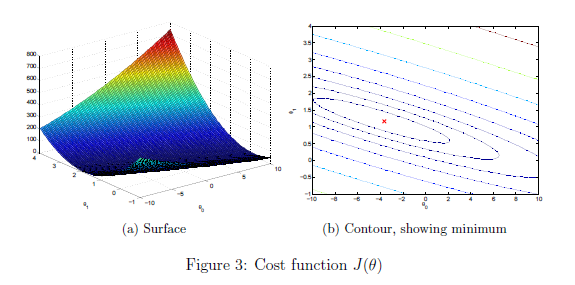

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

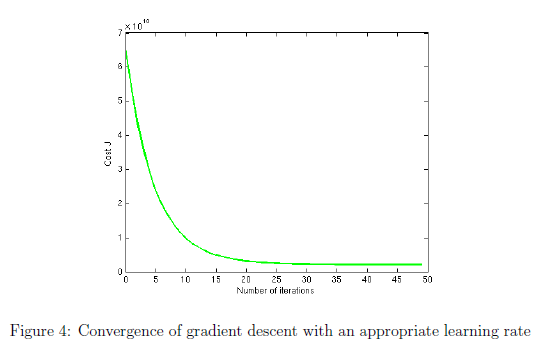

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 1;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

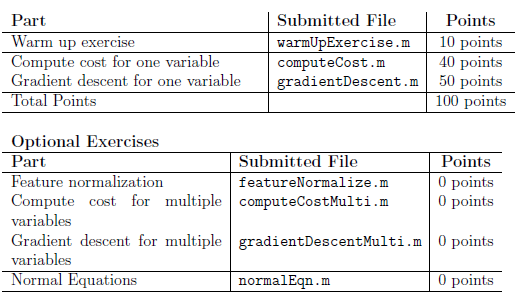

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.